DAC Range

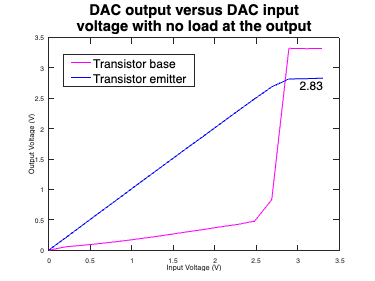

dac_input = [0 0.206451612903226 0.412903225806452 0.619354838709677 0.825806451612903 1.03225806451613 1.23870967741935 1.44516129032258 1.65161290322581 1.85806451612903 2.06451612903226 2.27096774193548 2.47741935483871 2.68387096774194 2.89032258064516 3.09677419354839 3.3];

dac_unbuff_no_load = [0.00029 0.05771 0.08159 0.1104 0.14257 0.17767 0.21611 0.25702 0.29951 0.3399 0.38418 0.42398 0.47831 0.8307 3.3212 3.3161 3.318];
dac_buff_no_load = [0.00384 0.20963 0.42009 0.6297 0.8366 1.0469 1.2543 1.462 1.6696 1.8732 2.0801 2.287 2.4899 2.6869 2.8172 2.8217 2.8304];

dac_unbuff_loaded = [0.00029 0.8202 1.0443 1.2606 1.4713 1.6842 1.8941 2.0981 2.307 2.5125 2.7173 2.9261 3.131 3.2658 3.262 3.252 3.2683];
dac_buff_loaded = [0.00002 0.20509 0.41189 0.6178 0.8227 1.0291 1.2318 1.4325 1.6364 1.8371 2.0325 2.2334 2.4415 2.5491 2.5788 2.579 2.5854];

figure();
plot(dac_input, dac_unbuff_no_load, 'm-x', dac_input, dac_buff_no_load, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output versus DAC input", "voltage with no load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_no_load(end), sprintf('%.2f', dac_buff_no_load(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_no_load.png');

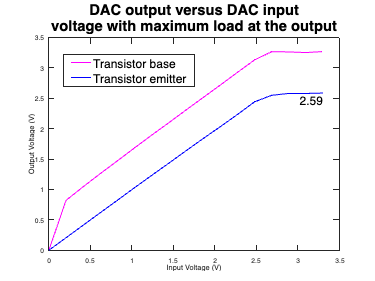


figure();
plot(dac_input, dac_unbuff_loaded, 'm-x', dac_input, dac_buff_loaded, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output versus DAC input", "voltage with maximum load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_loaded(end), sprintf('%.2f', dac_buff_loaded(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_loaded.png');


dac_input = dac_input(1:13);
dac_buff_no_load = dac_buff_no_load(1:13);
dac_buff_loaded = dac_buff_loaded(1:13);

coefficients_no_load = polyfit(dac_input, dac_buff_no_load, 1);
m_no_load = coefficients_no_load(1)

m_no_load = 1.0048

b_no_load = coefficients_no_load(2)

b_no_load = 0.0063

r = corrcoef(dac_input, dac_buff_no_load);
r_2_no_load = r(1,2)^2

r_2_no_load = 1.0000


coefficients_no_load = polyfit(dac_input, dac_buff_loaded, 1);
m_loaded = coefficients_no_load(1)

m_loaded = 0.9837

b_loaded = coefficients_no_load(2)

b_loaded = 0.0070

r = corrcoef(dac_input, dac_buff_loaded);
r_2_loaded = r(1,2)^2

r_2_loaded = 1.0000

ADC range

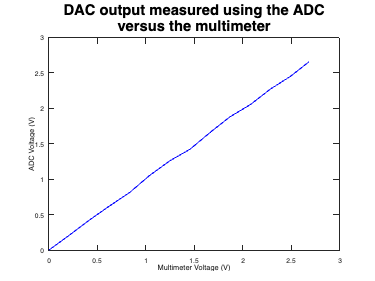

adc_multimeter = [0.00299 0.20852 0.41849 0.6282 0.8363 1.0419 1.2487 1.4556 1.6649 1.8689 2.0821 2.2859 2.4966 2.6888];
adc_bits = [0.00483516483516484 0.20952380952381 0.425494505494506 0.626153846153846 0.817142857142857 1.05648351648352 1.26117216117216 1.42315018315018 1.66168498168498 1.88087912087912 2.05575091575092 2.27172161172161 2.45465201465201 2.66095238095238];

figure();
plot(adc_multimeter, adc_bits, 'b-x');
xlabel('Multimeter Voltage (V)');
ylabel('ADC Voltage (V)');
title(["DAC output measured using the ADC", "versus the multimeter"], "FontSize", 22);
saveas(gcf, 'Report/Figures/Testing/ADC.png');


coefficients_adc = polyfit(adc_multimeter, adc_bits, 1);
m_adc = coefficients_adc(1)

m_adc = 0.9877

b_adc = coefficients_adc(2)

b_adc = 0.0082

r = corrcoef(adc_multimeter, adc_bits);
r_adc = r(1,2)^2

r_adc = 0.9997

Resistors

R = [0.02 1 1.21 1.52 1.88 2.26 2.68 3.42 3.85 4.84 5.59 6.72 7.49 8.2 9.9];
vr_ave = [1.04 1.95 2.13 2.42 2.7 3.06 3.45 4.09 4.48 5.35 5.96 6.91 7.52 8.09 9.39]/5;
vr_sin = [1.03 1.94 2.11 2.4 2.69 3.04 3.44 4.08 4.47 5.35 5.96 6.91 7.52 8.1 9.4]/5;

r = corrcoef(vr_ave, vr_sin);
r_r = r(1,2)^2

r_r = 1.0000


k = vr_ave * 5/105;
rm = k*100./(1-k);

% curveFitter(R, vr_ave)

r = corrcoef(R, rm);
r_rv = r(1,2)^2

r_rv = 0.9999

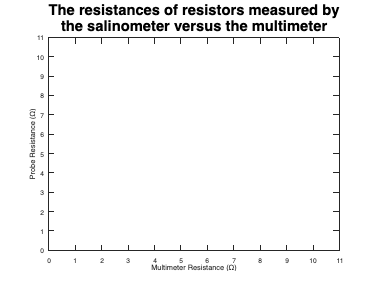


figure();
plot(R, rm, 'bx');
xlabel('Multimeter Resistance (Ω)');

ylabel('Probe Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_uncorrected.png');

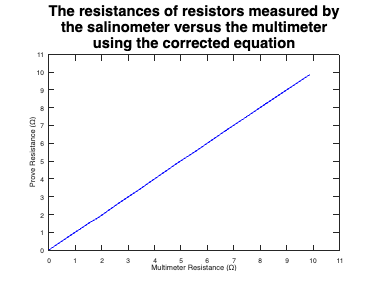


% (p1*x + p2)/(x + q1)
P1 = 17.4687;
P2 = 18.4643;
Q1 = 91.8315;

r_corr = (P2 - Q1 * vr_ave)./(vr_ave - P1);

figure();
plot(R, r_corr, 'b-x');
xlabel('Multimeter Resistance (Ω)');
ylabel('Prove Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter", "using the corrected equation"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_corrected.png');


coefficients_r = polyfit(R, r_corr, 1);
m_r = coefficients_r(1)

m_r = 1.0000

b_r = coefficients_r(2)

b_r = 8.4802e-05


r = corrcoef(R, r_corr);
r_r_corr = r(1,2)^2

r_r_corr = 1.0000

Linear Voltage Sweep

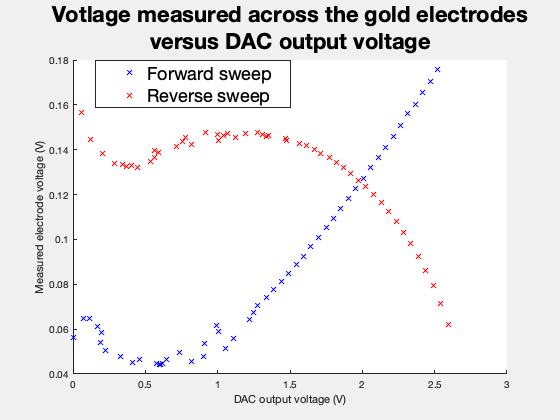

% first double sweep
figure();
hold on
graph("m", 'bx', "0,1,10,766;16,89,13,886;32,141,18,884;48,210,22,838;64,242,24,798;80,233,29,737;96,278,33,690;112,407,38,655;128,574,41,634;144,509,44,619;160,720,48,608;176,754,51,602;192,746,56,603;208,771,59,609;224,1016,63,621;240,801,69,637;256,1116,73,653;272,912,75,677;288,1307,80,704;304,1124,80,734;320,1375,88,764;336,1252,92,803;352,1233,92,841;368,1517,99,878;384,1546,102,922;400,1582,105,965;416,1658,109,1012;432,1721,113,1059;448,1787,118,1107;464,1847,121,1156;480,1913,125,1210;496,1975,129,1263;512,2039,132,1320;528,2108,136,1377;544,2171,140,1435;560,2234,144,1494;576,2298,148,1551;592,2361,151,1614;608,2425,154,1673;624,2489,160,1738;640,2554,162,1800;656,2618,166,1862;672,2682,171,1925;688,2745,174,1993;704,2809,178,2057;720,2873,182,2129;736,2938,185,2189;752,3001,190,2259;768,3064,193,2327;784,3128,197,2399;");
graph("m", 'rx', "806,3217,203,850;790,3152,199,974;774,3090,195,1083;758,3025,192,1174;742,2960,187,1260;726,2898,183,1338;710,2834,180,1410;694,2771,176,1473;678,2706,172,1534;662,2643,168,1590;646,2579,164,1641;630,2512,160,1685;614,2449,156,1726;598,2384,153,1764;582,2319,149,1800;566,2257,145,1836;550,2196,140,1862;534,2126,137,1889;518,2070,134,1913;502,2007,130,1936;486,1942,127,1951;470,1830,122,1969;454,1823,119,1980;438,1659,115,1994;422,1679,110,1998;406,1622,105,2002;390,1325,104,2012;374,1582,102,2013;358,1138,93,2015;342,1481,90,2011;326,1290,85,2000;310,1241,81,2002;294,1396,78,1987;278,968,76,1983;262,1246,74,1968;246,936,70,1959;230,1018,67,1944;214,890,62,1928;198,700,57,1909;182,732,54,1894;166,697,47,1866;150,665,47,1842;134,422,41,1820;118,498,39,1815;102,552,36,1804;86,460,32,1810;70,353,28,1825;54,253,22,1886;38,146,18,1972;22,73,15,2137;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Forward sweep", "Reverse sweep", "Position", [0.17 0.75 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus2.png");

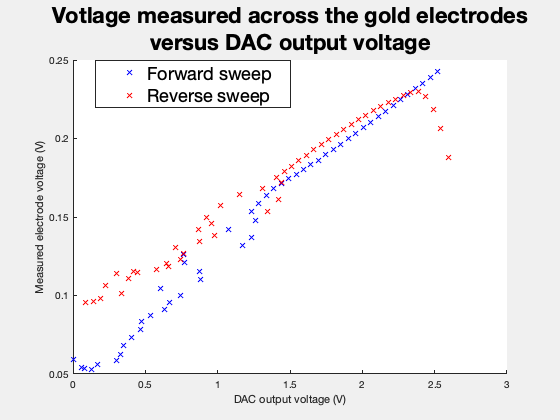

% with dac drain
figure();
hold on
graph("m", 'bx', "0,1,10,808;16,72,13,739;32,157,18,723;48,101,21,728;64,210,25,765;80,374,29,798;96,406,32,856;112,432,36,927;128,500,40,1001;144,578,44,1073;160,587,48,1135;176,664,51,1187;192,786,55,1241;208,826,61,1302;224,924,63,1362;240,752,69,1430;256,1095,72,1507;272,1083,74,1575;288,953,81,1653;304,945,85,1725;320,1450,84,1798;336,1533,89,1869;352,1337,93,1943;368,1564,98,2017;384,1531,102,2093;400,1594,105,2165;416,1659,109,2237;432,1722,113,2296;448,1786,117,2343;464,1850,121,2380;480,1913,125,2419;496,1977,128,2459;512,2041,132,2501;528,2106,136,2543;544,2170,140,2590;560,2233,144,2635;576,2298,148,2680;592,2362,151,2729;608,2425,155,2776;624,2489,159,2822;640,2553,163,2869;656,2617,167,2918;672,2681,170,2968;688,2745,175,3015;704,2809,178,3066;720,2873,182,3113;736,2937,186,3163;752,3001,189,3211;768,3064,193,3261;784,3128,197,3314;");
graph("m", 'rx', "806,3217,202,2563;790,3153,198,2820;774,3090,195,2983;758,3024,194,3091;742,2960,187,3138;726,2897,183,3130;710,2833,179,3104;694,2769,176,3073;678,2705,172,3041;662,2641,168,3007;646,2577,164,2971;630,2513,160,2932;614,2449,156,2896;598,2385,152,2853;582,2321,149,2811;566,2257,145,2768;550,2194,143,2723;534,2129,137,2678;518,2065,133,2633;502,2001,130,2585;486,1938,126,2538;470,1875,122,2490;454,1810,120,2443;438,1746,115,2393;422,1792,110,2345;406,1623,104,2296;390,1428,100,2245;374,1764,101,2202;358,1268,94,2151;342,1665,88,2092;326,1147,89,2039;310,1188,83,1991;294,1077,79,1940;278,1214,79,1884;262,1087,74,1834;246,876,68,1778;230,951,67,1727;214,926,61,1680;198,806,57,1642;182,819,54,1618;166,715,50,1594;150,517,47,1576;134,555,41,1564;118,376,37,1559;102,472,36,1513;86,275,32,1453;70,417,28,1383;54,238,23,1336;38,179,19,1311;22,106,15,1305;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Forward sweep", "Reverse sweep", "Position", [0.17 0.75 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus3.png");

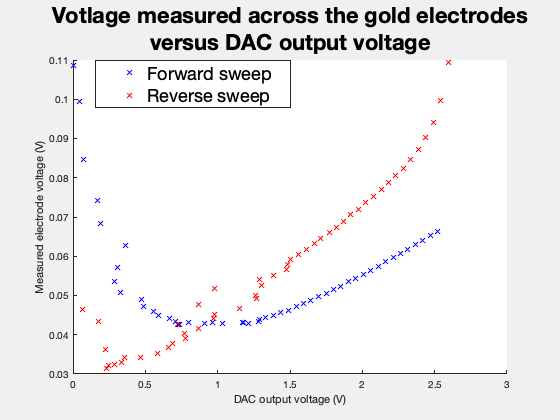

% with dac drain and prime x25
figure();
hold on
graph("m", 'bx', "0,1,10,1484;16,55,13,1357;32,89,16,1155;48,209,22,1013;64,235,23,934;80,451,28,858;96,382,32,780;112,358,36,730;128,406,40,694;144,586,44,669;160,606,46,645;176,691,52,627;192,736,56,612;208,827,59,604;224,878,65,593;240,989,65,587;256,904,71,583;272,914,73,583;288,1131,79,584;304,1456,85,590;320,1280,86,586;336,1193,90,589;352,1504,93,586;368,1462,98,590;384,1590,102,593;400,1599,105,598;416,1655,109,606;432,1722,113,613;448,1784,117,623;464,1851,120,632;480,1915,124,643;496,1977,128,654;512,2039,132,666;528,2107,136,678;544,2171,140,689;560,2234,144,702;576,2297,147,715;592,2362,151,730;608,2426,155,742;624,2490,159,757;640,2554,163,770;656,2617,167,785;672,2680,170,800;688,2746,174,814;704,2811,178,829;720,2873,182,844;736,2937,185,859;752,3000,189,874;768,3065,193,890;784,3129,197,905;");
graph("m", 'rx', "806,3217,203,1494;790,3152,198,1362;774,3089,196,1285;758,3025,191,1232;742,2961,188,1191;726,2898,183,1156;710,2834,179,1125;694,2770,176,1099;678,2706,172,1074;662,2642,168,1050;646,2576,164,1027;630,2512,160,1007;614,2447,156,982;598,2384,152,964;582,2323,149,939;566,2258,145,919;550,2196,141,900;534,2127,137,880;518,2071,133,862;502,1999,129,843;486,1936,125,825;470,1869,122,807;454,1842,118,790;438,1830,114,772;422,1720,111,753;406,1601,108,737;390,1618,101,719;374,1212,98,706;358,1569,92,684;342,1575,91,673;326,1076,85,651;310,1431,81,639;294,1212,82,615;278,1208,74,601;262,894,72,582;246,1076,67,567;230,958,64,551;214,963,60,532;198,851,56,516;182,817,53,501;166,724,49,482;150,581,46,467;134,419,41,448;118,352,37,442;102,287,34,429;86,302,32,440;70,443,27,466;54,278,26,493;38,220,19,591;22,79,15,635;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Forward sweep", "Reverse sweep", "Position", [0.17 0.75 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus5.png");

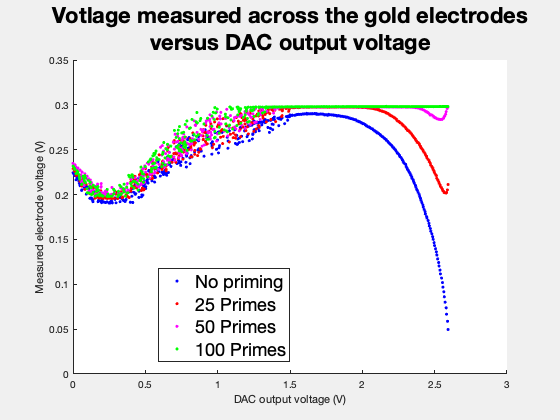

% with prime x 0-100
figure();
hold on
graph("m", 'b.', "806,3217,203,677;805,3213,203,802;803,3204,202,910;802,3201,202,1006;800,3192,202,1092;798,3185,201,1175;797,3181,200,1251;795,3173,200,1322;794,3169,200,1391;792,3161,200,1460;790,3152,199,1523;789,3148,199,1581;787,3140,198,1643;786,3136,197,1697;784,3128,198,1752;782,3121,197,1810;781,3117,197,1858;779,3110,196,1906;777,3101,196,1954;776,3097,196,1999;774,3089,196,2049;773,3085,195,2089;771,3078,194,2133;769,3069,195,2173;768,3065,194,2213;766,3057,193,2252;765,3053,193,2293;763,3046,193,2335;761,3036,192,2374;760,3033,192,2396;758,3023,192,2434;757,3020,192,2470;755,3012,191,2504;753,3005,190,2539;752,3001,189,2573;750,2992,188,2610;748,2985,189,2643;747,2981,188,2672;745,2974,188,2702;744,2970,189,2732;742,2960,188,2764;740,2954,187,2792;739,2948,186,2808;737,2941,186,2843;736,2938,186,2869;734,2928,186,2902;732,2922,185,2927;731,2918,185,2955;729,2908,184,2977;728,2905,184,3001;726,2897,183,3028;724,2890,182,3052;723,2884,182,3072;721,2878,182,3093;719,2869,181,3115;718,2865,181,3135;716,2858,181,3155;715,2854,181,3188;713,2845,180,3201;711,2836,180,3218;710,2832,180,3236;708,2826,180,3255;707,2821,179,3273;705,2813,178,3294;703,2804,175,3308;702,2801,178,3326;700,2794,178,3344;698,2784,176,3358;697,2780,176,3372;695,2772,176,3390;694,2768,176,3405;692,2762,175,3418;690,2752,175,3432;689,2750,175,3443;687,2740,174,3457;686,2736,174,3472;684,2730,174,3484;682,2722,172,3495;681,2716,173,3507;679,2708,172,3518;678,2704,172,3530;676,2699,171,3541;674,2688,171,3556;673,2686,171,3569;671,2677,170,3577;669,2671,169,3587;668,2665,170,3596;666,2658,169,3608;665,2652,169,3613;663,2644,168,3626;661,2637,168,3635;660,2634,167,3643;658,2626,167,3653;657,2621,167,3661;655,2614,166,3669;653,2606,166,3670;652,2602,166,3686;650,2592,165,3692;649,2590,166,3700;647,2581,165,3708;645,2574,165,3717;644,2570,164,3728;642,2561,164,3733;640,2554,163,3739;639,2549,162,3745;637,2543,162,3754;636,2537,162,3760;634,2527,162,3765;632,2521,162,3773;631,2517,161,3777;629,2507,160,3789;628,2505,160,3799;626,2496,160,3806;624,2490,159,3809;623,2484,159,3813;621,2478,156,3820;620,2472,159,3824;618,2466,157,3832;616,2458,157,3838;615,2452,157,3842;613,2444,156,3847;611,2438,156,3850;610,2433,156,3853;608,2426,155,3869;607,2421,156,3868;605,2413,154,3871;603,2404,154,3877;602,2402,153,3878;600,2392,153,3885;599,2390,153,3886;597,2380,152,3887;595,2374,152,3894;594,2368,152,3894;592,2363,152,3901;590,2354,151,3906;589,2349,151,3906;587,2340,150,3908;586,2339,150,3911;584,2332,149,3915;582,2323,150,3914;581,2317,149,3918;579,2311,148,3920;578,2306,148,3921;576,2298,148,3921;574,2291,147,3925;573,2287,147,3927;571,2277,147,3930;570,2273,148,3931;568,2265,145,3927;566,2260,145,3934;565,2253,145,3934;563,2246,144,3937;561,2237,144,3937;560,2234,144,3941;558,2227,144,3941;557,2220,143,3942;555,2215,142,3943;553,2202,142,3944;552,2198,142,3946;550,2194,142,3945;549,2192,141,3950;547,2184,140,3937;545,2173,140,3944;544,2170,140,3945;542,2160,139,3943;541,2155,139,3946;539,2148,139,3951;537,2144,138,3952;536,2141,138,3954;534,2130,136,3954;532,2123,137,3956;531,2117,138,3953;529,2109,136,3952;528,2105,136,3952;526,2098,136,3952;524,2088,135,3953;523,2088,135,3962;521,2074,134,3964;520,2071,134,3961;518,2070,134,3961;516,2055,133,3960;515,2053,133,3961;513,2044,133,3959;512,2041,132,3961;510,2034,132,3960;508,2024,132,3958;507,2021,130,3960;505,2012,131,3957;503,2006,133,3954;502,2004,130,3965;500,1999,130,3960;499,1987,129,3957;497,1981,128,3957;495,1973,128,3955;494,1971,128,3955;492,1962,128,3951;491,1954,128,3950;489,1953,128,3951;487,1938,127,3949;486,1938,127,3951;484,1925,126,3949;482,1925,124,3947;481,1918,125,3944;479,1909,125,3942;478,1905,124,3939;476,1903,124,3936;474,1862,123,3941;473,1882,122,3938;471,1882,122,3934;470,1878,122,3935;468,1866,122,3927;466,1860,121,3923;465,1851,122,3920;463,1844,120,3922;462,1837,120,3913;460,1830,122,3917;458,1845,120,3917;457,1856,119,3915;455,1727,119,3910;453,1840,118,3910;452,1784,118,3908;450,1793,118,3897;449,1787,118,3903;447,1780,117,3895;445,1757,116,3892;444,1771,116,3895;442,1716,115,3888;441,1770,115,3881;439,1712,115,3881;437,1783,115,3874;436,1782,114,3879;434,1728,114,3872;433,1723,114,3877;431,1718,113,3874;429,1702,113,3867;428,1702,112,3867;426,1647,113,3872;424,1482,111,3865;423,1841,109,3860;421,1693,112,3859;420,1640,111,3855;418,1665,110,3853;416,1660,110,3853;415,1671,109,3856;413,1657,110,3851;412,1554,106,3846;410,1542,108,3832;408,1629,107,3832;407,1619,108,3833;405,1602,107,3828;403,1582,108,3832;402,1649,106,3824;400,1593,105,3826;399,1546,106,3809;397,1709,104,3802;395,1573,105,3822;394,1556,102,3814;392,1815,102,3809;391,1717,103,3798;389,1708,101,3801;387,1534,104,3785;386,1619,102,3790;384,1589,101,3781;383,1524,101,3785;381,1318,102,3775;379,1765,103,3779;378,1503,100,3776;376,1502,100,3768;374,1254,101,3763;373,1672,97,3750;371,1483,97,3755;370,1434,99,3748;368,1439,98,3745;366,1586,96,3741;365,1694,98,3737;363,1713,98,3718;362,1553,95,3718;360,1134,94,3717;358,1389,98,3714;357,1472,94,3700;355,1342,93,3699;354,1597,92,3701;352,1566,94,3686;350,1254,92,3684;349,1278,92,3676;347,1685,91,3675;345,1246,96,3678;344,1219,95,3673;342,1149,95,3667;341,1146,94,3661;339,1543,92,3654;337,1500,92,3640;336,1542,90,3645;334,1405,88,3630;333,1033,89,3635;331,1446,89,3617;329,1076,85,3612;328,1493,89,3611;326,1168,86,3604;325,1323,86,3603;323,996,89,3598;321,1428,85,3590;320,1147,87,3591;318,1169,89,3587;316,1539,83,3576;315,1413,84,3578;313,1067,88,3563;312,1239,87,3560;310,1017,86,3574;308,983,83,3568;307,1512,82,3550;305,1077,86,3548;304,1331,81,3545;302,1455,83,3535;300,1041,84,3538;299,1196,81,3533;297,1427,84,3523;295,1189,83,3512;294,1393,81,3508;292,1186,80,3508;291,914,82,3500;289,1412,80,3499;287,1406,76,3493;286,1004,81,3485;284,1257,78,3474;283,1192,75,3467;281,932,77,3465;279,885,80,3458;278,899,78,3448;276,1253,74,3442;275,1329,74,3435;273,990,77,3439;271,1080,73,3428;270,1231,74,3419;268,939,72,3419;266,1071,75,3407;265,1091,75,3399;263,1100,74,3391;262,1081,75,3388;260,1043,73,3381;258,827,71,3371;257,1248,70,3364;255,979,69,3357;254,882,69,3354;252,1191,72,3345;250,972,68,3340;249,974,68,3327;247,1014,70,3323;246,974,67,3314;244,1124,67,3313;242,1021,70,3303;241,809,66,3299;239,1002,69,3289;237,944,63,3281;236,944,68,3274;234,861,66,3265;233,849,66,3257;231,905,67,3249;229,840,66,3245;228,729,63,3228;226,926,67,3227;225,968,62,3221;223,913,64,3214;221,830,64,3204;220,892,65,3203;218,1004,61,3200;217,823,61,3193;215,816,63,3189;213,786,59,3182;212,924,59,3174;210,840,61,3159;208,973,60,3149;207,701,60,3147;205,764,59,3141;204,746,59,3141;202,685,56,3128;200,696,58,3118;199,727,57,3121;197,728,57,3102;196,651,56,3096;194,788,57,3100;192,648,57,3088;191,736,55,3078;189,763,54,3069;187,780,55,3072;186,818,54,3064;184,800,54,3051;183,801,54,3056;181,795,53,3039;179,775,53,3034;178,804,53,3025;176,698,51,3011;175,749,52,3011;173,703,51,2989;171,707,51,2991;170,654,51,2977;168,563,50,2979;167,637,51,2956;165,636,50,2948;163,633,49,2946;162,677,48,2939;160,700,47,2920;158,610,47,2927;157,637,47,2922;155,644,47,2905;154,618,47,2899;152,603,48,2879;150,531,46,2885;149,607,45,2861;147,624,44,2850;146,551,45,2844;144,620,43,2841;142,623,43,2822;141,501,44,2825;139,517,42,2826;138,502,41,2818;136,570,43,2799;134,572,42,2790;133,566,42,2780;131,499,41,2772;129,478,41,2767;128,523,41,2764;126,538,40,2743;125,534,39,2734;123,393,40,2743;121,591,39,2724;120,599,37,2722;118,505,39,2705;117,588,37,2697;115,565,38,2686;113,407,38,2681;112,360,40,2680;110,424,38,2661;109,455,34,2655;107,360,36,2657;105,452,37,2649;104,432,36,2642;102,326,35,2630;100,447,33,2624;99,404,35,2622;97,328,34,2623;96,292,33,2618;94,492,34,2614;92,513,30,2610;91,245,32,2607;89,317,32,2612;88,278,33,2608;86,319,32,2603;84,337,32,2604;83,308,32,2605;81,270,30,2613;79,310,28,2602;78,369,30,2604;76,241,26,2622;75,171,28,2622;73,215,29,2622;71,244,24,2626;70,333,28,2624;68,252,26,2631;67,244,26,2636;65,219,24,2642;63,170,26,2642;62,167,24,2648;60,164,24,2657;59,357,24,2663;57,144,25,2672;55,159,22,2676;54,154,22,2681;52,189,23,2694;50,211,22,2707;49,213,22,2719;47,292,21,2729;46,206,20,2731;44,114,19,2737;42,158,21,2753;41,189,20,2758;39,237,20,2769;38,146,18,2776;36,176,20,2782;34,74,17,2793;33,75,18,2800;31,101,17,2817;30,141,21,2825;28,96,16,2841;26,119,16,2850;25,60,16,2866;23,82,15,2876;21,110,15,2887;20,54,14,2901;18,82,14,2915;17,101,14,2926;15,51,13,2934;13,26,13,2955;12,36,12,2966;10,57,12,2982;9,32,12,3000;7,13,11,3020;5,16,11,3032;4,4,11,3050;2,1,10,3062;");
graph("m", 'r.', "806,3217,203,2883;805,3212,202,2801;803,3204,202,2761;802,3200,201,2754;800,3192,201,2758;798,3184,201,2761;797,3181,201,2774;795,3173,200,2789;794,3169,200,2809;792,3161,199,2833;790,3152,199,2855;789,3149,199,2877;787,3141,198,2902;786,3136,198,2927;784,3129,198,2953;782,3120,196,2977;781,3117,197,3017;779,3110,196,3035;777,3101,196,3063;776,3097,195,3085;774,3089,194,3110;773,3086,195,3134;771,3077,194,3157;769,3068,194,3179;768,3065,194,3205;766,3057,193,3227;765,3053,193,3250;763,3044,193,3268;761,3035,192,3290;760,3032,192,3314;758,3024,192,3332;757,3020,191,3352;755,3013,190,3371;753,3005,191,3390;752,3000,190,3412;750,2992,189,3429;748,2984,189,3446;747,2981,188,3464;745,2974,188,3483;744,2970,187,3501;742,2961,187,3520;740,2953,186,3522;739,2948,186,3543;737,2941,186,3557;736,2937,186,3573;734,2929,185,3592;732,2922,185,3605;731,2917,185,3621;729,2910,184,3636;728,2905,184,3650;726,2898,184,3665;724,2889,183,3679;723,2885,183,3691;721,2877,182,3705;719,2869,182,3704;718,2865,182,3720;716,2857,182,3732;715,2853,181,3750;713,2844,180,3765;711,2837,180,3773;710,2832,180,3784;708,2826,179,3793;707,2822,178,3804;705,2813,179,3816;703,2805,178,3823;702,2801,178,3834;700,2795,178,3842;698,2784,174,3850;697,2780,176,3858;695,2774,176,3876;694,2768,175,3884;692,2762,175,3894;690,2753,175,3903;689,2750,174,3908;687,2741,174,3917;686,2737,173,3922;684,2730,174,3930;682,2721,173,3934;681,2716,173,3945;679,2709,172,3950;678,2704,172,3961;676,2698,171,3966;674,2689,171,3969;673,2685,171,3977;671,2677,170,3983;669,2670,170,3988;668,2666,170,3991;666,2656,169,3995;665,2653,169,4001;663,2644,168,4002;661,2636,168,4007;660,2635,168,4011;658,2624,167,4015;657,2623,167,4021;655,2614,166,4021;653,2606,166,4026;652,2601,166,4030;650,2593,166,4031;649,2590,165,4034;647,2580,165,4036;645,2574,164,4039;644,2570,164,4043;642,2562,163,4043;640,2555,163,4045;639,2549,162,4046;637,2543,162,4047;636,2539,162,4048;634,2528,161,4048;632,2523,160,4050;631,2517,161,4053;629,2508,160,4053;628,2507,160,4054;626,2497,160,4055;624,2488,158,4055;623,2485,159,4057;621,2478,158,4057;620,2471,158,4057;618,2464,157,4058;616,2459,157,4058;615,2453,157,4058;613,2444,156,4057;611,2439,156,4058;610,2432,156,4059;608,2426,155,4060;607,2420,155,4059;605,2414,155,4060;603,2404,154,4059;602,2403,154,4060;600,2392,153,4060;599,2392,153,4060;597,2379,152,4060;595,2375,152,4060;594,2370,151,4060;592,2362,152,4060;590,2353,151,4060;589,2351,150,4059;587,2343,150,4061;586,2339,150,4060;584,2332,150,4060;582,2322,149,4060;581,2315,149,4060;579,2311,148,4060;578,2304,148,4061;576,2298,148,4060;574,2291,148,4061;573,2286,147,4061;571,2279,147,4061;570,2276,146,4061;568,2264,146,4060;566,2260,145,4061;565,2255,145,4060;563,2248,144,4060;561,2237,144,4060;560,2235,144,4060;558,2227,142,4060;557,2221,143,4060;555,2212,142,4060;553,2202,141,4060;552,2199,142,4059;550,2192,141,4060;549,2193,141,4060;547,2183,140,4059;545,2173,140,4060;544,2170,140,4060;542,2164,139,4060;541,2156,139,4060;539,2147,139,4063;537,2145,138,4060;536,2141,138,4061;534,2130,137,4060;532,2124,137,4060;531,2116,136,4060;529,2109,136,4060;528,2107,136,4060;526,2096,135,4060;524,2090,135,4061;523,2088,135,4059;521,2074,134,4059;520,2079,134,4060;518,2066,134,4060;516,2056,133,4060;515,2054,134,4060;513,2044,132,4060;512,2041,132,4059;510,2032,132,4059;508,2029,131,4059;507,2023,131,4058;505,2012,131,4059;503,2001,130,4058;502,1997,130,4059;500,1997,129,4059;499,1989,129,4059;497,1982,128,4058;495,1974,128,4058;494,1971,128,4058;492,1966,128,4058;491,1952,128,4056;489,1949,127,4055;487,1938,128,4056;486,1933,126,4055;484,1927,126,4054;482,1924,126,4054;481,1916,125,4056;479,1910,124,4055;478,1904,124,4054;476,1900,122,4054;474,1876,124,4055;473,1939,123,4053;471,1887,123,4053;470,1895,122,4051;468,1866,121,4050;466,1861,125,4048;465,1852,121,4047;463,1846,121,4047;462,1838,121,4046;460,1845,120,4043;458,1826,120,4043;457,1797,119,4040;455,1779,118,4040;453,1826,118,4040;452,1777,118,4036;450,1795,118,4035;449,1792,118,4033;447,1787,117,4031;445,1773,117,4029;444,1770,116,4030;442,1855,115,4025;441,1787,116,4027;439,1704,116,4023;437,1676,114,4019;436,1796,114,4017;434,1733,114,4016;433,1721,114,4015;431,1716,113,4009;429,1621,113,4010;428,1796,111,4005;426,1524,111,4001;424,1594,111,4001;423,1850,109,3996;421,1664,111,3984;420,1674,110,3983;418,1666,109,3982;416,1657,109,3977;415,1653,108,3976;413,1653,109,3973;412,1498,110,3969;410,1435,106,3966;408,1688,109,3961;407,1520,109,3961;405,1580,108,3951;403,1442,106,3954;402,1648,107,3949;400,1599,105,3938;399,1590,106,3929;397,1570,104,3927;395,1793,106,3931;394,1628,102,3926;392,1590,106,3925;391,1789,102,3918;389,1450,102,3917;387,1527,103,3906;386,1449,102,3902;384,1471,102,3899;383,1402,102,3903;381,1310,103,3892;379,1631,100,3893;378,1287,102,3886;376,1238,102,3882;374,1542,97,3882;373,1697,100,3872;371,1488,97,3876;370,1475,97,3862;368,1472,98,3856;366,1461,97,3860;365,1418,97,3847;363,1376,99,3846;362,1658,93,3836;360,1738,98,3840;358,1439,93,3827;357,1533,93,3824;355,1215,96,3836;354,1552,93,3825;352,1544,94,3818;350,1182,95,3805;349,1425,94,3806;347,1475,96,3804;345,1257,95,3800;344,1246,95,3791;342,1315,95,3784;341,1139,94,3784;339,1592,93,3781;337,1239,89,3762;336,1457,88,3758;334,1495,88,3761;333,1598,86,3755;331,1370,86,3741;329,1185,86,3736;328,1572,88,3728;326,1434,91,3721;325,1279,85,3718;323,1118,90,3718;321,1483,84,3703;320,1270,86,3697;318,1168,84,3693;316,1551,83,3692;315,1111,85,3682;313,1135,87,3679;312,1129,87,3676;310,1028,86,3667;308,1376,81,3665;307,1505,82,3653;305,1085,85,3644;304,1350,81,3648;302,1395,83,3634;300,1090,83,3635;299,1113,79,3624;297,1289,83,3615;295,1438,79,3609;294,1375,81,3596;292,1266,82,3601;291,969,83,3598;289,1395,80,3588;287,958,77,3590;286,1006,81,3580;284,1118,75,3571;283,1117,76,3565;281,914,80,3559;279,869,79,3552;278,948,78,3546;276,1137,74,3538;275,1341,74,3530;273,1029,75,3524;271,1050,73,3517;270,1283,72,3507;268,867,75,3516;266,941,71,3508;265,1152,75,3501;263,1206,74,3494;262,1135,74,3490;260,1038,73,3483;258,815,72,3472;257,1010,72,3464;255,911,68,3458;254,817,71,3445;252,1196,70,3443;250,1011,68,3435;249,1091,68,3428;247,1096,68,3419;246,991,68,3412;244,956,67,3404;242,1044,70,3400;241,812,66,3394;239,951,69,3388;237,948,66,3376;236,1079,67,3374;234,881,66,3362;233,865,65,3354;231,888,67,3350;229,1044,66,3342;228,739,64,3335;226,923,65,3328;225,1069,62,3323;223,910,62,3318;221,848,64,3311;220,1020,63,3305;218,1010,61,3301;217,904,61,3291;215,798,61,3282;213,904,60,3276;212,943,61,3268;210,873,62,3260;208,680,58,3243;207,771,60,3240;205,766,59,3229;204,850,58,3221;202,882,59,3220;200,699,57,3212;199,690,58,3203;197,764,56,3194;196,806,56,3181;194,807,56,3180;192,799,56,3170;191,758,55,3156;189,674,55,3146;187,792,54,3148;186,774,55,3143;184,622,54,3126;183,703,54,3121;181,799,54,3113;179,762,53,3112;178,668,52,3103;176,799,51,3091;175,668,51,3088;173,583,51,3064;171,675,50,3060;170,726,50,3059;168,666,50,3055;167,570,50,3032;165,635,50,3037;163,613,49,3031;162,677,49,3023;160,574,48,3007;158,532,47,3008;157,635,47,3003;155,684,47,2978;154,669,46,2971;152,497,46,2960;150,538,45,2960;149,527,45,2963;147,514,44,2937;146,586,44,2927;144,496,44,2920;142,506,42,2922;141,527,45,2926;139,532,42,2910;138,498,42,2896;136,584,42,2886;134,562,41,2877;133,568,41,2870;131,521,41,2857;129,542,41,2850;128,552,41,2848;126,544,40,2834;125,594,39,2829;123,499,40,2827;121,611,38,2814;120,607,37,2801;118,586,38,2791;117,496,39,2782;115,412,37,2773;113,371,38,2766;112,422,36,2756;110,407,35,2753;109,401,35,2739;107,366,37,2737;105,331,36,2727;104,455,36,2723;102,466,33,2704;100,461,33,2701;99,426,35,2694;97,312,34,2687;96,292,33,2682;94,482,34,2685;92,228,31,2677;91,248,32,2679;89,303,33,2675;88,316,32,2676;86,356,28,2671;84,332,29,2668;83,287,32,2674;81,260,31,2670;79,296,29,2671;78,383,29,2671;76,188,26,2674;75,421,28,2681;73,221,29,2679;71,195,28,2684;70,220,24,2690;68,266,27,2693;67,243,26,2701;65,219,25,2703;63,223,24,2715;62,193,23,2724;60,244,22,2732;59,186,23,2736;57,140,25,2746;55,291,24,2748;54,173,24,2750;52,203,23,2765;50,219,23,2778;49,239,22,2788;47,291,20,2798;46,208,20,2802;44,103,20,2810;42,172,21,2820;41,203,20,2825;39,195,19,2833;38,151,18,2840;36,169,19,2851;34,73,17,2859;33,78,16,2867;31,113,17,2885;30,145,17,2897;28,103,16,2911;26,99,16,2920;25,59,16,2934;23,73,15,2944;21,85,15,2955;20,57,15,2976;18,89,13,2985;17,96,13,2994;15,55,13,3007;13,26,13,3022;12,37,13,3032;10,40,12,3048;9,35,12,3065;7,14,11,3084;5,15,13,3100;4,5,11,3117;2,2,10,3128;");
graph("m", 'm.', "806,3216,203,4061;804,3209,202,4041;802,3201,202,3993;801,3197,202,3953;799,3188,201,3925;797,3181,200,3902;796,3177,200,3888;794,3169,200,3879;793,3164,200,3873;791,3156,199,3872;789,3148,199,3874;788,3145,199,3874;786,3137,198,3875;785,3133,198,3879;783,3124,197,3883;781,3117,196,3889;780,3112,196,3895;778,3105,196,3901;776,3097,195,3908;775,3093,196,3919;773,3086,195,3928;772,3082,194,3936;770,3073,194,3942;768,3065,193,3939;767,3061,194,3948;765,3053,193,3964;764,3048,192,3973;762,3041,192,3981;760,3032,192,3989;759,3028,192,3996;757,3020,192,4002;756,3016,191,4008;754,3009,190,4015;752,3000,190,4021;751,2997,190,4026;749,2988,189,4031;747,2981,188,4035;746,2977,188,4041;744,2972,188,4042;743,2966,188,4047;741,2957,187,4048;739,2949,186,4051;738,2945,186,4053;736,2937,185,4055;735,2932,185,4056;733,2925,185,4057;731,2919,185,4059;730,2914,185,4059;728,2906,184,4060;727,2901,184,4060;725,2894,183,4060;723,2884,183,4060;722,2881,183,4060;720,2873,182,4061;718,2865,181,4060;717,2861,181,4061;715,2855,180,4061;714,2851,181,4061;712,2841,180,4064;710,2833,180,4062;709,2830,179,4062;707,2822,179,4061;706,2816,178,4061;704,2809,178,4062;702,2801,181,4062;701,2798,178,4065;699,2790,177,4062;697,2780,177,4062;696,2777,176,4062;694,2769,176,4062;693,2765,176,4062;691,2758,176,4063;689,2749,175,4062;688,2745,174,4063;686,2736,174,4063;685,2734,173,4063;683,2725,173,4063;681,2716,172,4064;680,2712,172,4063;678,2704,172,4062;677,2701,172,4063;675,2693,171,4064;673,2685,172,4063;672,2682,171,4064;670,2673,170,4064;668,2667,170,4064;667,2662,169,4064;665,2652,169,4064;664,2650,169,4064;662,2641,168,4064;660,2635,168,4064;659,2630,167,4064;657,2623,167,4064;656,2617,166,4064;654,2608,166,4064;652,2603,165,4064;651,2598,166,4064;649,2588,165,4064;648,2586,164,4064;646,2576,164,4065;644,2570,161,4064;643,2566,164,4064;641,2557,163,4064;639,2551,162,4064;638,2545,162,4065;636,2537,162,4064;635,2531,161,4064;633,2525,161,4065;631,2516,161,4064;630,2511,160,4065;628,2506,159,4064;627,2501,160,4065;625,2494,159,4065;623,2485,160,4065;622,2481,160,4065;620,2473,158,4065;619,2467,158,4065;617,2462,158,4064;615,2456,157,4065;614,2449,157,4064;612,2441,156,4065;610,2433,159,4065;609,2430,155,4065;607,2420,155,4064;606,2417,154,4065;604,2410,154,4065;602,2403,154,4064;601,2398,154,4066;599,2389,153,4065;598,2384,152,4065;596,2377,152,4065;594,2368,152,4065;593,2365,152,4064;591,2356,151,4065;589,2351,151,4064;588,2344,150,4065;586,2339,150,4064;585,2337,150,4066;583,2328,149,4065;581,2316,149,4065;580,2313,148,4066;578,2305,148,4068;577,2303,148,4065;575,2293,147,4064;573,2286,147,4065;572,2282,147,4062;570,2275,146,4065;569,2267,146,4064;567,2263,145,4065;565,2252,145,4065;564,2246,144,4065;562,2241,144,4065;560,2234,144,4064;559,2229,144,4064;557,2221,143,4064;556,2216,143,4064;554,2210,142,4064;552,2199,141,4065;551,2195,142,4064;549,2192,141,4065;548,2183,141,4065;546,2177,140,4064;544,2170,140,4064;543,2164,140,4064;541,2156,139,4064;540,2156,138,4064;538,2142,138,4065;536,2141,138,4065;535,2135,138,4064;533,2128,137,4066;531,2118,137,4065;530,2117,137,4064;528,2107,136,4064;527,2102,136,4063;525,2093,136,4063;523,2084,135,4062;522,2083,135,4063;520,2071,135,4064;519,2067,133,4062;517,2060,134,4064;515,2051,133,4064;514,2050,132,4064;512,2040,132,4063;511,2040,132,4063;509,2030,132,4062;507,2017,131,4064;506,2017,132,4065;504,2008,130,4063;502,2006,130,4063;501,1994,131,4063;499,1990,129,4063;498,1985,130,4062;496,1978,128,4063;494,1970,128,4063;493,1965,128,4063;491,1956,128,4062;490,1954,128,4062;488,1941,128,4062;486,1942,127,4062;485,1928,126,4063;483,1922,125,4065;481,1917,125,4062;480,1914,125,4062;478,1904,125,4062;477,1898,124,4062;475,1891,123,4064;473,1919,123,4061;472,1936,123,4061;470,1877,122,4061;469,1865,122,4062;467,1858,122,4061;465,1851,124,4061;464,1848,121,4062;462,1838,121,4062;461,1834,120,4062;459,1875,120,4061;457,1756,120,4062;456,1875,119,4060;454,1818,118,4061;452,1775,118,4060;451,1798,118,4062;449,1790,117,4061;448,1787,117,4062;446,1777,117,4059;444,1700,116,4060;443,1725,116,4061;441,1792,115,4062;440,1704,114,4062;438,1739,115,4062;436,1701,114,4060;435,1690,114,4060;433,1722,113,4060;432,1718,113,4061;430,1702,113,4060;428,1660,112,4061;427,1684,113,4060;425,1702,110,4058;423,1813,109,4058;422,1812,110,4057;420,1755,110,4053;419,1689,111,4054;417,1661,109,4052;415,1659,109,4052;414,1696,109,4053;412,1657,109,4051;411,1625,107,4048;409,1626,108,4046;407,1620,108,4045;406,1734,109,4043;404,1760,106,4042;403,1605,106,4040;401,1564,106,4036;399,1626,105,4033;398,1429,106,4032;396,1558,106,4028;394,1319,106,4027;393,1732,102,4022;391,1524,101,4018;390,1553,103,4017;388,1539,105,4015;386,1492,103,4007;385,1535,105,4006;383,1631,103,3999;382,1664,102,3997;380,1475,101,3992;378,1606,98,3989;377,1231,100,3984;375,1268,102,3980;373,1596,98,3965;372,1720,98,3969;370,1477,98,3963;369,1502,97,3962;367,1543,98,3959;365,1609,100,3949;364,1175,99,3944;362,1514,94,3940;361,1445,94,3935;359,1350,93,3931;357,1259,93,3924;356,1428,96,3923;354,1428,94,3921;353,1404,94,3917;351,1531,92,3907;349,1323,92,3902;348,1384,93,3900;346,1199,96,3897;344,1306,96,3888;343,1263,95,3882;341,1171,95,3874;340,1605,88,3874;338,1152,91,3867;336,1381,88,3855;335,1143,91,3850;333,1041,90,3850;332,1175,91,3840;330,1572,91,3833;328,1558,89,3826;327,1496,90,3822;325,1252,85,3821;324,1139,88,3817;322,1058,85,3808;320,1270,88,3806;319,1521,89,3796;317,1446,88,3786;315,1048,85,3786;314,1051,86,3781;312,1192,83,3773;311,1176,87,3766;309,977,87,3759;307,1387,81,3758;306,1341,82,3747;304,1396,81,3731;303,1098,84,3722;301,1477,80,3737;299,1208,82,3724;298,1199,84,3719;296,1121,84,3710;294,1426,81,3699;293,1299,82,3695;291,1110,79,3690;290,1159,81,3688;288,1181,77,3677;286,1064,81,3675;285,1159,80,3665;283,1240,78,3655;282,949,77,3652;280,876,79,3647;278,1188,74,3638;277,1099,77,3629;275,1327,74,3622;274,1141,78,3617;272,898,75,3615;270,1175,75,3603;269,941,73,3598;267,967,73,3592;265,943,75,3585;264,1025,75,3578;262,1178,74,3574;261,1080,74,3568;259,934,70,3561;257,1233,70,3545;256,898,69,3537;254,860,69,3529;253,887,70,3530;251,1017,69,3522;249,976,69,3514;248,1019,71,3507;246,989,68,3499;245,1000,68,3492;243,1128,68,3486;241,818,66,3480;240,766,68,3474;238,1107,66,3467;236,903,67,3459;235,751,65,3450;233,897,67,3441;232,927,64,3437;230,801,66,3432;228,870,66,3421;227,934,65,3415;225,1016,62,3409;224,938,65,3400;222,777,62,3392;220,968,63,3383;219,909,61,3375;217,824,61,3371;216,913,60,3362;214,794,61,3354;212,975,61,3350;211,928,61,3335;209,695,59,3337;207,763,61,3329;206,932,59,3321;204,866,58,3304;203,907,58,3292;201,720,58,3288;199,807,57,3283;198,820,57,3267;196,687,56,3260;195,832,55,3255;193,874,55,3251;191,810,56,3252;190,777,54,3233;188,671,56,3220;186,777,54,3221;185,712,54,3212;183,638,53,3211;182,650,52,3191;180,807,52,3187;178,738,53,3188;177,685,52,3163;175,615,52,3167;174,787,51,3150;172,616,52,3141;170,622,50,3143;169,601,51,3123;167,690,50,3130;166,687,49,3123;164,733,49,3112;162,590,48,3099;161,593,49,3087;159,704,48,3073;157,623,47,3072;156,701,47,3058;154,673,46,3046;153,665,46,3038;151,658,46,3033;149,606,46,3021;148,588,46,3012;146,596,45,3006;145,508,46,2996;143,571,44,2991;141,532,44,2986;140,656,43,2980;138,501,42,2959;137,501,42,2958;135,563,41,2944;133,553,40,2935;132,545,40,2926;130,615,40,2917;128,589,41,2910;127,544,40,2903;125,601,39,2900;124,466,41,2898;122,579,40,2881;120,548,38,2869;119,553,37,2861;117,460,38,2850;116,564,37,2851;114,334,38,2837;112,408,37,2830;111,430,37,2823;109,420,34,2818;108,446,34,2809;106,475,35,2798;104,445,38,2787;103,473,33,2782;101,447,35,2774;99,395,35,2765;98,355,35,2759;96,420,33,2752;95,394,34,2750;93,388,31,2744;91,243,32,2742;90,274,33,2737;88,334,32,2734;87,343,30,2728;85,324,29,2728;83,330,29,2719;82,276,31,2722;80,257,31,2725;78,393,29,2726;77,392,26,2727;75,166,28,2736;74,198,27,2746;72,191,29,2735;70,244,25,2746;69,259,26,2753;67,245,26,2762;66,226,23,2770;64,289,26,2770;62,154,25,2774;61,278,23,2782;59,137,23,2787;58,205,23,2790;56,173,24,2791;54,168,24,2797;53,198,24,2813;51,209,22,2826;49,240,22,2841;48,241,22,2852;46,196,20,2857;45,95,22,2868;43,149,21,2882;41,211,20,2890;40,242,18,2897;38,149,18,2904;37,159,19,2912;35,73,18,2919;33,84,19,2930;32,75,17,2938;30,149,17,2951;29,124,17,2959;27,134,16,2969;25,63,16,2983;24,77,15,2999;22,121,15,3009;20,57,14,3021;19,68,14,3030;17,101,14,3046;16,39,13,3059;14,78,13,3072;12,35,12,3086;11,61,12,3102;9,33,12,3122;8,42,12,3133;6,24,12,3152;4,5,11,3170;3,18,11,3182;1,0,10,3203;");
graph("m", 'g.', "806,3216,203,4070;805,3213,202,4071;803,3204,202,4070;802,3200,202,4070;800,3193,201,4071;798,3185,201,4070;797,3181,201,4070;795,3173,200,4070;794,3169,200,4069;792,3160,200,4069;790,3153,199,4070;789,3149,199,4070;787,3141,198,4069;786,3137,198,4069;784,3129,197,4069;782,3120,196,4069;781,3117,196,4069;779,3110,196,4069;777,3102,196,4069;776,3096,196,4069;774,3089,195,4069;773,3085,195,4069;771,3077,194,4069;769,3069,194,4069;768,3064,193,4069;766,3057,193,4069;765,3053,193,4069;763,3043,192,4069;761,3036,192,4069;760,3033,192,4069;758,3024,192,4069;757,3021,191,4069;755,3012,190,4069;753,3004,189,4068;752,3001,189,4069;750,2992,189,4069;748,2985,189,4069;747,2980,188,4069;745,2974,188,4069;744,2970,188,4068;742,2961,187,4069;740,2953,187,4069;739,2948,187,4069;737,2942,186,4069;736,2937,186,4069;734,2928,186,4068;732,2921,185,4069;731,2918,184,4069;729,2910,184,4069;728,2905,184,4069;726,2898,184,4068;724,2889,183,4068;723,2884,182,4069;721,2877,182,4069;719,2869,182,4068;718,2864,181,4069;716,2858,180,4068;715,2853,181,4068;713,2845,180,4069;711,2837,181,4069;710,2833,180,4069;708,2826,179,4069;707,2821,179,4068;705,2812,178,4069;703,2804,178,4069;702,2801,177,4068;700,2795,177,4068;698,2786,177,4068;697,2780,177,4069;695,2772,176,4069;694,2769,176,4069;692,2761,175,4068;690,2753,175,4068;689,2749,175,4069;687,2741,174,4069;686,2736,173,4069;684,2730,173,4068;682,2720,173,4068;681,2716,173,4068;679,2707,172,4068;678,2704,171,4068;676,2698,171,4068;674,2688,172,4072;673,2686,171,4069;671,2676,170,4068;669,2670,170,4069;668,2666,170,4069;666,2656,169,4069;665,2652,169,4068;663,2642,168,4069;661,2635,168,4068;660,2635,168,4069;658,2625,168,4068;657,2621,168,4069;655,2613,167,4069;653,2606,166,4068;652,2603,166,4068;650,2593,166,4069;649,2589,165,4068;647,2581,164,4069;645,2575,164,4068;644,2570,164,4069;642,2561,163,4068;640,2553,162,4068;639,2550,162,4068;637,2542,163,4069;636,2538,162,4068;634,2529,162,4069;632,2522,161,4069;631,2517,161,4069;629,2508,160,4069;628,2505,160,4069;626,2496,159,4068;624,2489,159,4068;623,2486,159,4068;621,2479,158,4069;620,2474,158,4068;618,2464,157,4068;616,2455,157,4069;615,2454,157,4068;613,2446,157,4069;611,2437,155,4067;610,2432,156,4069;608,2426,156,4068;607,2421,155,4068;605,2414,155,4068;603,2405,153,4068;602,2402,154,4068;600,2395,153,4068;599,2390,153,4068;597,2382,152,4068;595,2374,152,4068;594,2368,152,4068;592,2362,151,4068;590,2354,151,4068;589,2350,150,4068;587,2341,150,4068;586,2340,150,4068;584,2332,149,4068;582,2322,149,4068;581,2315,148,4068;579,2310,148,4068;578,2305,148,4068;576,2298,147,4067;574,2290,147,4067;573,2286,147,4067;571,2277,147,4069;570,2276,146,4068;568,2267,146,4067;566,2261,146,4069;565,2253,144,4068;563,2247,145,4068;561,2237,144,4068;560,2234,144,4067;558,2227,143,4067;557,2221,143,4067;555,2217,142,4066;553,2202,142,4069;552,2199,142,4068;550,2196,141,4068;549,2190,141,4067;547,2182,140,4067;545,2174,140,4068;544,2169,139,4068;542,2163,139,4067;541,2159,139,4068;539,2149,139,4068;537,2141,138,4067;536,2142,137,4067;534,2127,138,4068;532,2123,138,4067;531,2116,137,4067;529,2109,136,4067;528,2106,136,4067;526,2100,135,4067;524,2090,135,4066;523,2089,134,4066;521,2075,134,4067;520,2073,134,4067;518,2069,134,4067;516,2057,132,4066;515,2052,133,4067;513,2045,132,4067;512,2040,132,4066;510,2032,132,4067;508,2025,131,4066;507,2021,132,4066;505,2010,130,4067;503,2001,130,4066;502,2006,130,4066;500,1990,129,4066;499,1990,129,4066;497,1983,128,4066;495,1974,128,4065;494,1972,128,4066;492,1957,128,4066;491,1961,128,4066;489,1946,127,4064;487,1939,127,4067;486,1943,127,4066;484,1926,125,4065;482,1925,124,4066;481,1916,125,4066;479,1908,124,4066;478,1906,124,4065;476,1895,124,4065;474,1877,123,4067;473,1935,124,4064;471,1934,122,4064;470,1882,122,4065;468,1871,122,4064;466,1854,121,4065;465,1852,121,4065;463,1848,120,4064;462,1838,120,4066;460,1843,120,4067;458,1727,120,4064;457,1821,119,4064;455,1849,119,4063;453,1830,119,4065;452,1791,118,4065;450,1790,117,4064;449,1791,117,4064;447,1787,117,4065;445,1770,116,4065;444,1659,116,4064;442,1826,115,4064;441,1721,115,4063;439,1861,115,4064;437,1745,114,4063;436,1769,114,4063;434,1730,113,4064;433,1729,114,4062;431,1716,113,4062;429,1772,112,4062;428,1662,112,4063;426,1753,111,4062;424,1685,111,4062;423,1781,109,4061;421,1691,112,4061;420,1694,110,4061;418,1672,110,4061;416,1657,109,4062;415,1659,109,4061;413,1595,109,4062;412,1710,108,4060;410,1408,106,4062;408,1596,108,4062;407,1570,107,4062;405,1805,107,4061;403,1627,107,4060;402,1649,106,4060;400,1596,106,4060;399,1607,105,4062;397,1740,104,4062;395,1345,106,4062;394,1709,102,4059;392,1559,104,4059;391,1561,103,4060;389,1651,101,4059;387,1545,102,4060;386,1549,103,4058;384,1503,102,4060;383,1526,101,4058;381,1417,103,4058;379,1478,101,4055;378,1597,98,4054;376,1217,102,4053;374,1354,102,4052;373,1673,99,4050;371,1493,97,4047;370,1652,100,4044;368,1438,99,4036;366,1369,98,4034;365,1416,97,4032;363,1237,97,4032;362,1359,98,4028;360,1549,94,4023;358,1486,93,4016;357,1433,93,4016;355,1527,93,4010;354,1538,93,4006;352,1484,93,4002;350,1485,96,3998;349,1426,94,3993;347,1646,93,3988;345,1203,96,3981;344,1063,95,3978;342,1224,94,3972;341,1625,89,3971;339,1591,92,3963;337,1307,91,3953;336,1477,89,3943;334,1414,88,3943;333,1585,87,3936;331,1191,91,3926;329,1552,90,3919;328,1309,88,3913;326,1462,91,3906;325,1329,85,3900;323,1154,89,3891;321,1496,84,3888;320,1096,87,3887;318,1021,89,3873;316,1212,84,3873;315,1355,83,3866;313,1090,87,3855;312,977,87,3850;310,1512,86,3843;308,1056,83,3838;307,1498,85,3831;305,1067,84,3820;304,1439,84,3815;302,1310,85,3806;300,1123,81,3803;299,962,83,3797;297,1343,83,3787;295,1406,80,3780;294,1338,82,3772;292,1190,79,3769;291,913,82,3764;289,1254,82,3754;287,1007,76,3745;286,998,76,3735;284,1370,76,3727;283,1298,76,3713;281,903,79,3711;279,870,80,3706;278,1318,77,3697;276,1217,74,3690;275,1323,75,3683;273,949,77,3677;271,933,75,3668;270,1254,73,3663;268,898,74,3655;266,1038,75,3646;265,1074,76,3638;263,1150,74,3631;262,1059,74,3615;260,960,72,3607;258,885,70,3599;257,1219,71,3601;255,1213,69,3593;254,913,72,3581;252,1164,70,3574;250,1149,68,3571;249,1045,68,3564;247,1013,70,3555;246,1005,67,3545;244,1021,66,3543;242,958,70,3532;241,779,66,3522;239,925,68,3516;237,959,64,3505;236,948,68,3502;234,811,66,3493;233,968,65,3484;231,904,64,3481;229,839,66,3467;228,949,65,3457;226,888,63,3451;225,965,65,3442;223,902,62,3433;221,796,63,3428;220,923,64,3412;218,809,61,3412;217,979,61,3402;215,911,60,3394;213,712,61,3392;212,934,60,3381;210,772,61,3372;208,705,59,3355;207,694,59,3356;205,768,58,3341;204,697,58,3329;202,816,58,3321;200,685,57,3319;199,839,57,3313;197,835,56,3302;196,719,56,3291;194,790,56,3287;192,668,57,3274;191,739,57,3264;189,717,55,3256;187,662,55,3257;186,717,55,3251;184,646,54,3227;183,825,53,3217;181,770,52,3207;179,683,53,3200;178,700,52,3204;176,791,52,3178;175,793,52,3181;173,620,51,3156;171,761,50,3156;170,583,50,3148;168,713,50,3148;167,699,49,3139;165,711,48,3132;163,675,48,3127;162,673,48,3109;160,583,48,3090;158,592,48,3076;157,673,47,3077;155,595,46,3046;154,606,47,3041;152,504,45,3031;150,509,45,3028;149,478,45,3023;147,481,44,3011;146,642,45,2999;144,583,43,2992;142,487,44,2996;141,514,44,2993;139,606,42,2972;138,583,42,2962;136,575,43,2950;134,577,42,2939;133,530,42,2932;131,513,40,2929;129,605,41,2917;128,545,41,2911;126,494,41,2901;125,438,39,2887;123,558,41,2888;121,400,38,2871;120,503,38,2861;118,412,38,2849;117,461,36,2839;115,524,38,2830;113,433,38,2821;112,348,37,2810;110,559,35,2800;109,435,34,2796;107,356,37,2792;105,389,37,2780;104,440,36,2770;102,471,33,2758;100,466,33,2752;99,416,35,2746;97,300,34,2737;96,390,32,2728;94,408,32,2727;92,227,30,2722;91,248,32,2717;89,301,32,2709;88,227,32,2711;86,336,29,2706;84,324,30,2705;83,259,32,2707;81,256,31,2704;79,308,27,2701;78,384,30,2699;76,450,27,2706;75,292,27,2703;73,194,26,2711;71,241,25,2717;70,193,29,2705;68,243,25,2715;67,235,25,2725;65,212,24,2726;63,157,26,2730;62,166,24,2735;60,351,22,2743;59,231,23,2749;57,136,24,2753;55,121,24,2758;54,173,24,2764;52,202,23,2778;50,217,22,2792;49,219,22,2797;47,293,21,2809;46,207,20,2815;44,120,19,2820;42,156,21,2834;41,192,20,2844;39,213,20,2852;38,144,18,2858;36,174,19,2872;34,74,18,2882;33,77,18,2890;31,108,17,2908;30,148,18,2918;28,97,16,2937;26,131,16,2945;25,58,16,2964;23,94,15,2973;21,107,15,2983;20,55,14,2994;18,85,14,3007;17,101,13,3019;15,52,13,3032;13,26,12,3050;12,36,12,3061;10,41,12,3077;9,35,12,3092;7,14,12,3114;5,14,11,3128;4,4,10,3153;2,1,8,3163;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
ylim([0, 0.35])
legend("No priming", "25 Primes", "50 Primes", "100 Primes", "Position", [0.3 0.2 0.2, 0.1], "FontSize", 18);
hold of
saveas(gcf, "Report/Figures/Testing/Aus7.png");

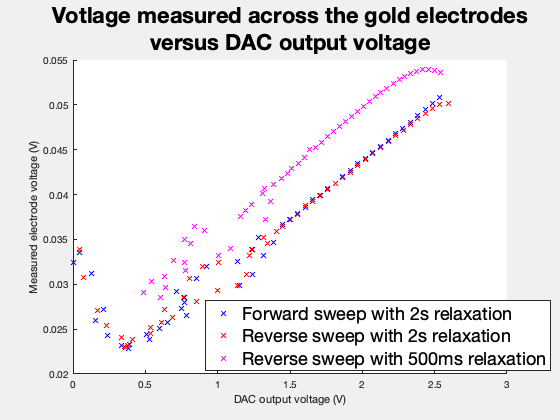

% with voltage relaxation 2s and 500ms
figure();
hold on
graph("m", 'bx', "0,1,10,443;16,53,13,458;32,157,18,426;48,259,21,371;64,195,26,354;80,296,29,332;96,482,32,318;112,476,35,312;128,417,41,316;145,656,44,325;161,629,48,333;177,740,51,342;193,814,56,351;209,973,60,362;225,931,65,372;241,957,68,382;257,960,73,389;274,884,77,398;290,1426,77,407;306,1059,84,418;322,1539,89,425;338,1148,93,436;354,1410,95,444;370,1637,98,453;386,1538,102,462;403,1720,106,473;419,1595,110,481;435,1742,114,490;451,1793,118,500;467,1859,122,508;483,1922,125,517;499,1991,128,526;515,2055,133,538;531,2119,136,545;548,2184,140,555;564,2250,144,563;580,2314,148,573;596,2377,152,582;612,2442,156,593;628,2506,159,601;644,2570,163,610;660,2634,168,619;677,2702,171,629;693,2766,175,639;709,2829,178,647;725,2894,182,656;741,2957,186,666;757,3020,190,675;773,3085,194,684;789,3148,198,693;");
graph("m", 'rx', "806,3217,202,684;789,3148,198,683;773,3086,194,677;757,3020,191,670;741,2957,186,661;725,2895,183,653;709,2832,179,644;693,2766,176,636;677,2703,172,627;660,2634,168,617;644,2570,164,609;628,2506,160,599;612,2443,156,590;596,2379,152,580;580,2315,148,572;564,2248,144,563;548,2184,141,554;531,2118,136,544;515,2053,133,535;499,1992,129,529;483,1927,126,516;467,1864,122,508;451,1801,118,498;435,1749,113,490;419,1632,110,481;402,1669,106,471;386,1530,102,463;370,1518,98,453;354,1246,94,442;338,1109,91,436;322,1488,88,424;306,1001,85,419;290,1412,78,407;274,1237,76,400;257,948,71,389;241,1063,67,383;225,789,65,371;209,856,61,359;193,758,56,351;177,664,53,344;161,668,48,334;145,512,44,325;128,439,40,315;112,447,36,314;96,467,34,316;80,420,28,329;64,289,26,347;48,213,22,370;32,88,17,420;16,55,13,463;");
graph("m", 'mx', "790,3154,199,731;777,3101,196,735;764,3048,192,737;751,2996,189,736;739,2949,186,734;726,2898,183,730;713,2844,180,726;701,2797,177,721;688,2745,174,715;675,2693,171,708;662,2641,168,702;650,2592,165,695;637,2541,162,687;624,2490,158,680;612,2442,156,673;599,2391,153,665;586,2338,150,657;574,2290,147,650;561,2237,144,642;548,2183,140,634;535,2132,138,625;523,2083,135,618;510,2032,132,614;497,1982,128,602;485,1935,125,594;472,1877,122,586;459,1839,119,578;447,1786,116,571;434,1724,114,562;421,1643,112,555;408,1629,107,548;396,1698,104,536;383,1528,101,531;370,1476,97,522;358,1441,94,513;345,1650,90,508;332,1043,91,497;320,1127,84,491;307,959,81,478;294,1012,78,471;281,1355,75,464;269,1251,71,453;256,861,72,446;243,955,70,442;231,963,63,431;218,787,62,421;205,670,60,413;193,791,56,405;180,605,53,397;167,748,50,390;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Forward sweep with 2s relaxation", "Reverse sweep with 2s relaxation", "Reverse sweep with 500ms relaxation", "Position", [0.5 0.15 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus8.png");

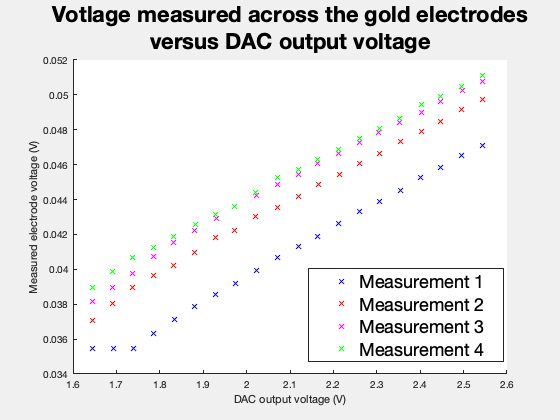

% with voltage relaxation consistency
figure();
hold on
graph("m", 'bx', "512,2042,132,484;526,2100,135,484;541,2158,138,484;556,2217,142,496;570,2276,146,507;585,2334,149,517;600,2393,153,526;614,2450,156,535;629,2510,160,545;644,2571,163,555;659,2629,167,564;673,2685,170,572;688,2746,174,582;703,2805,178,591;717,2861,181,599;732,2922,184,608;747,2980,188,618;761,3035,192,626;776,3097,194,635;791,3156,198,643;");
graph("m", 'rx', "512,2042,132,506;526,2098,136,519;541,2156,139,532;556,2216,142,541;570,2273,146,549;585,2334,149,559;600,2393,152,571;614,2448,156,576;629,2508,160,587;644,2571,163,594;659,2629,167,603;673,2686,170,612;688,2747,174,620;703,2805,177,629;717,2861,181,637;732,2921,184,646;747,2981,187,654;761,3036,191,662;776,3097,195,671;791,3157,199,679;");
graph("m", 'mx', "512,2042,132,521;526,2097,135,532;541,2156,139,543;556,2217,142,556;570,2274,145,567;585,2334,149,576;600,2395,152,586;614,2447,156,595;629,2509,160,604;644,2570,163,612;659,2629,167,620;673,2685,170,629;688,2745,174,637;703,2805,178,645;717,2860,180,653;732,2920,185,661;747,2981,188,669;761,3036,192,677;776,3098,195,686;791,3156,198,693;");
graph("m", 'gx', "512,2041,132,532;526,2098,135,544;541,2156,138,555;556,2217,142,563;570,2274,146,572;585,2337,149,581;600,2394,152,589;614,2447,156,595;629,2508,160,606;644,2570,163,618;659,2629,166,624;673,2685,170,632;688,2745,174,640;703,2805,177,648;717,2861,180,656;732,2920,184,664;747,2981,187,675;761,3036,192,681;776,3097,195,689;791,3157,199,698;");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.55 0.2 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus10.png");

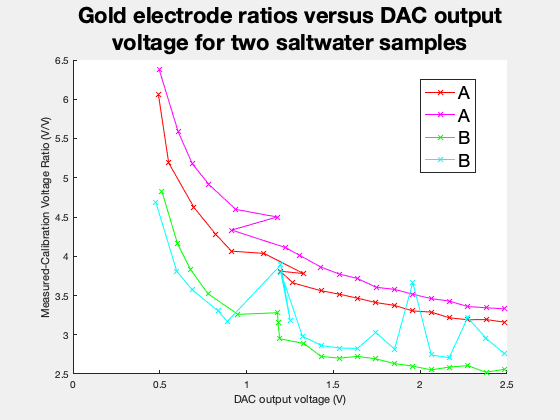

% with voltage relaxation consistency. A vs B
figure();
hold on
graph("r", 'r-x', "150,610,45,273;182,684,53,275;215,864,61,282;248,1022,69,295;281,1133,77,313;314,1365,83,335;346,1649,95,359;379,1481,100,381;412,1572,109,399;445,1773,116,413;478,1905,124,436;510,2033,131,454;543,2165,139,474;576,2297,147,496;609,2429,155,512;642,2561,163,536;674,2689,171,550;707,2821,178,568;740,2953,186,594;773,3085,194,613;");
graph("r", 'm-x', "150,616,45,287;182,752,53,296;215,852,61,316;248,972,69,339;281,1163,77,354;314,1459,82,369;346,1134,90,390;379,1521,101,415;412,1622,108,433;445,1772,116,448;478,1905,123,464;510,2033,131,487;543,2166,139,501;576,2298,147,526;609,2429,155,545;642,2561,163,564;674,2689,170,583;707,2821,178,598;740,2953,186,622;773,3085,194,646;");
graph("r", 'g-x', "150,636,45,217;182,746,54,225;215,839,60,230;248,965,69,243;281,1179,77,251;314,1462,82,269;346,1466,90,284;379,1477,100,295;412,1651,108,312;445,1773,116,316;478,1906,124,335;510,2033,131,357;543,2165,140,377;576,2298,147,387;609,2429,155,403;642,2561,163,416;674,2689,170,440;707,2821,178,464;740,2953,186,469;773,3085,194,497;");
graph("r", 'c-x', "150,592,45,211;182,741,53,202;215,851,61,218;248,1037,69,228;281,1103,77,244;314,1485,82,319;346,1552,92,293;379,1486,100,379;412,1640,108,322;445,1775,116,332;478,1906,124,351;510,2033,132,373;543,2165,139,421;576,2298,147,414;609,2429,155,568;642,2561,163,447;674,2689,171,463;707,2821,179,576;740,2952,186,550;773,3084,194,535;");
title(["Gold electrode ratios versus DAC output", "voltage for two saltwater samples"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("A","A","B","B", "Position", [0.75 0.65 0.1, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus12.png");

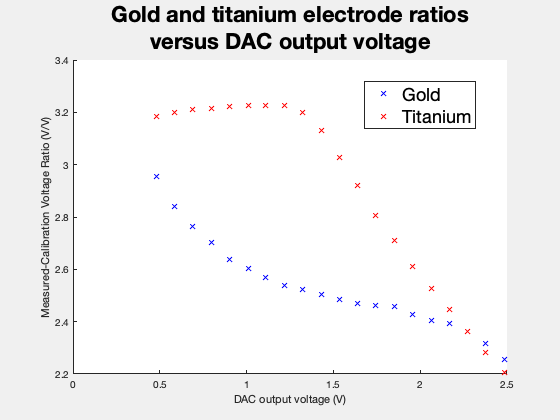

% with voltage relaxation and prime x25
figure();
hold on
graph("r", 'bx', "150,596,348,1028;182,724,421,1196;215,855,496,1370;248,987,571,1543;281,1119,646,1705;314,1251,720,1875;346,1379,794,2040;379,1510,869,2205;412,1642,943,2378;445,1774,1018,2549;478,1905,1094,2720;510,2032,1167,2881;543,2165,1243,3060;576,2297,1318,3239;609,2428,1392,3378;642,2561,1467,3529;674,2689,1540,3685;707,2821,1616,3818;740,2952,1690,3914;773,3084,1765,3983;");
graph("r", 'rx', "150,596,349,1111;182,724,421,1347;215,855,495,1590;248,987,571,1836;281,1119,646,2082;314,1251,721,2326;346,1379,794,2563;379,1510,869,2805;412,1642,944,3020;445,1773,1018,3188;478,1905,1094,3313;510,2033,1167,3408;543,2165,1242,3483;576,2297,1317,3567;609,2429,1393,3636;642,2561,1467,3708;674,2689,1540,3768;707,2821,1615,3813;740,2952,1689,3855;773,3084,1765,3895;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Gold", "Titanium", "Position", [0.65 0.7 0.2, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/AusTi15.png");

PSU rated samples.

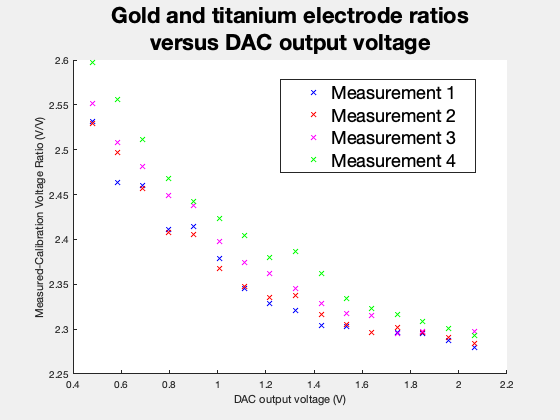

% Au 34.8PSU 15C
figure();
hold on
graphm("r", 'bx', "150,596,348,881;182,724,421,1037;215,855,495,1218;248,987,570,1374;281,1119,646,1560;314,1250,720,1713;346,1379,793,1860;379,1510,868,2021;412,1642,943,2188;445,1774,1018,2346;478,1906,1093,2517;510,2033,1167,2680;543,2165,1241,2850;576,2297,1316,3021;609,2429,1391,3181;642,2561,1466,3341;674,2689,1539,3491;707,2821,1614,3630;740,2952,1688,3769;773,3084,1763,3865;");
graphm("r", 'rx', "150,596,348,880;182,724,421,1051;215,855,495,1216;248,987,571,1375;281,1119,646,1554;314,1251,720,1705;346,1379,793,1862;379,1510,868,2027;412,1642,941,2200;445,1774,1018,2358;478,1905,1094,2522;510,2033,1167,2680;543,2165,1241,2856;576,2297,1316,3022;609,2429,1391,3187;642,2561,1466,3349;674,2689,1539,3501;707,2821,1613,3654;740,2952,1688,3778;773,3084,1764,3870;");
graphm("r", 'mx', "150,596,348,888;182,724,421,1056;215,855,495,1228;248,986,570,1396;281,1119,646,1575;314,1251,720,1726;346,1378,794,1885;379,1510,868,2050;412,1641,943,2212;445,1774,1018,2371;478,1905,1094,2535;510,2033,1166,2699;543,2165,1241,2848;576,2297,1316,3023;609,2429,1391,3200;642,2561,1466,3368;674,2689,1539,3514;707,2821,1614,3655;740,2952,1689,3776;773,3084,1763,3876;");
graphm("r", 'gx', "150,596,348,904;182,724,421,1076;215,855,495,1243;248,987,571,1409;281,1119,646,1578;314,1250,720,1745;346,1379,793,1907;379,1510,868,2066;412,1642,943,2250;445,1773,1018,2405;478,1905,1094,2553;510,2033,1166,2709;543,2165,1241,2875;576,2297,1316,3038;609,2429,1392,3203;642,2561,1466,3362;674,2689,1539,3535;707,2821,1613,3684;740,2952,1688,3808;773,3084,1763,3906;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus16.png");

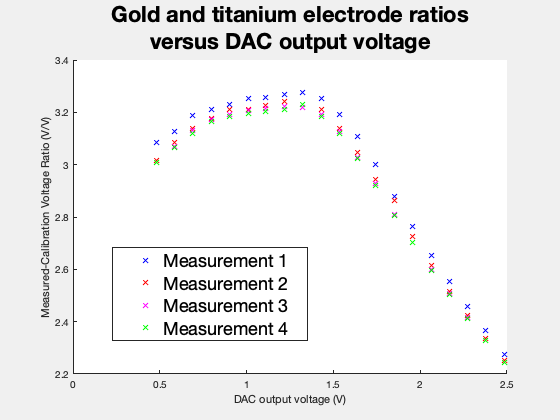

% Ti 34.8PSU 15C
figure();
hold on
graph("r", 'bx', "150,595,348,1074;182,724,421,1317;215,855,494,1574;248,987,571,1834;281,1119,646,2087;314,1251,720,2341;346,1379,794,2587;379,1511,869,2840;412,1642,943,3088;445,1773,1019,3313;478,1905,1094,3492;510,2033,1167,3628;543,2165,1242,3729;576,2297,1317,3789;609,2429,1391,3842;642,2562,1466,3891;674,2688,1540,3930;707,2821,1614,3967;740,2952,1689,3996;773,3084,1764,4014;");
graph("r", 'rx', "150,596,349,1053;182,724,421,1298;215,856,496,1557;248,987,571,1813;281,1120,646,2073;314,1251,721,2315;346,1379,794,2561;379,1510,868,2813;412,1641,944,3049;445,1773,1017,3264;478,1906,1094,3432;510,2033,1166,3550;543,2165,1241,3651;576,2297,1316,3766;609,2429,1391,3789;642,2561,1466,3833;674,2689,1540,3875;707,2821,1614,3911;740,2952,1688,3943;773,3084,1763,3967;");
graph("r", 'mx', "150,596,348,1047;182,724,421,1292;215,855,495,1550;248,987,570,1808;281,1120,646,2062;314,1251,720,2309;346,1379,793,2550;379,1510,868,2797;412,1642,943,3036;445,1774,1018,3251;478,1905,1093,3419;510,2033,1166,3531;543,2165,1240,3629;576,2297,1316,3698;609,2429,1391,3761;642,2561,1466,3813;674,2689,1539,3858;707,2821,1613,3895;740,2952,1688,3930;773,3084,1763,3958;");
graph("r", 'gx', "150,596,348,1047;182,724,421,1290;215,856,496,1548;248,987,571,1808;281,1119,646,2056;314,1251,721,2303;346,1379,794,2544;379,1510,869,2790;412,1642,943,3045;445,1773,1018,3242;478,1905,1093,3411;510,2033,1166,3527;543,2165,1241,3625;576,2297,1316,3693;609,2429,1391,3758;642,2561,1467,3810;674,2689,1539,3856;707,2821,1614,3895;740,2952,1688,3929;773,3084,1763,3956;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.2 0.25 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Ti16.png");

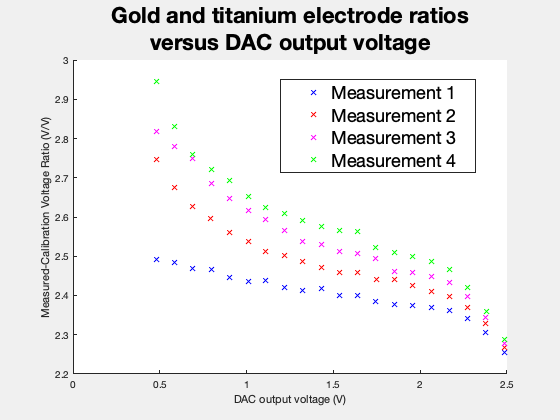

% Au 24.4PSU 21.7C
figure();
hold on
graph("r", 'bx', "150,596,348,867;182,724,421,1046;215,856,496,1224;248,987,571,1408;281,1119,646,1580;314,1251,721,1756;346,1379,794,1936;379,1511,869,2103;412,1642,944,2277;445,1774,1020,2467;478,1906,1095,2629;510,2033,1167,2801;543,2165,1243,2964;576,2297,1318,3134;609,2429,1393,3309;642,2561,1468,3477;674,2689,1541,3640;707,2820,1616,3782;740,2952,1690,3895;773,3084,1766,3980;");
graph("r", 'rx', "150,596,347,953;182,724,421,1126;215,855,496,1303;248,986,571,1482;281,1119,646,1654;314,1251,720,1827;346,1379,794,1994;379,1510,869,2174;412,1641,944,2347;445,1773,1019,2517;478,1905,1094,2690;510,2033,1167,2868;543,2166,1243,3033;576,2297,1318,3218;609,2429,1392,3378;642,2561,1468,3538;674,2689,1540,3693;707,2821,1615,3828;740,2952,1690,3934;773,3084,1765,4000;");
graph("r", 'mx', "150,596,348,981;182,723,420,1167;215,855,496,1364;248,987,571,1534;281,1119,646,1710;314,1251,721,1886;346,1379,794,2060;379,1510,869,2229;412,1642,944,2396;445,1774,1018,2575;478,1905,1094,2748;510,2033,1167,2925;543,2165,1242,3099;576,2297,1319,3247;609,2429,1392,3422;642,2561,1468,3594;674,2689,1540,3747;707,2821,1615,3870;740,2952,1690,3960;773,3084,1764,4016;");
graph("r", 'gx', "150,596,348,1025;182,723,421,1192;215,855,496,1369;248,987,570,1551;281,1119,646,1739;314,1251,721,1912;346,1379,794,2084;379,1510,869,2267;412,1642,944,2446;445,1773,1019,2625;478,1905,1094,2807;510,2033,1167,2990;543,2165,1242,3134;576,2297,1318,3309;609,2429,1393,3482;642,2561,1468,3651;674,2689,1541,3801;707,2821,1616,3913;740,2953,1690,3988;773,3084,1765,4038;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus17.png");

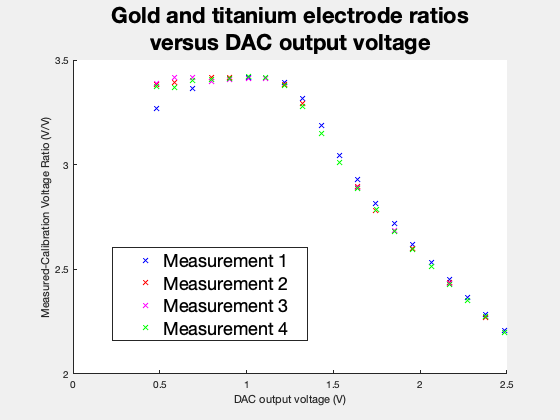

% Ti 24.4PSU 21.7C
figure();
hold on
graph("r", 'bx', "150,596,348,1138;182,724,421,1418;215,855,496,1668;248,987,571,1939;281,1119,646,2201;314,1251,721,2463;346,1379,794,2709;379,1510,869,2949;412,1641,944,3130;445,1773,1019,3249;478,1905,1095,3335;510,2033,1168,3419;543,2165,1242,3495;576,2298,1318,3582;609,2429,1394,3651;642,2561,1468,3717;674,2689,1541,3779;707,2820,1616,3822;740,2952,1691,3863;773,3084,1766,3899;");
graph("r", 'rx', "150,596,348,1178;182,724,421,1429;215,855,496,1688;248,987,570,1947;281,1119,646,2206;314,1251,721,2467;346,1378,794,2714;379,1510,869,2940;412,1642,943,3105;445,1773,1019,3210;478,1906,1095,3296;510,2033,1167,3379;543,2165,1242,3455;576,2297,1318,3541;609,2428,1392,3616;642,2561,1467,3686;674,2688,1540,3750;707,2821,1615,3796;740,2952,1690,3840;773,3084,1765,3881;");
graph("r", 'mx', "150,596,349,1182;182,724,421,1438;215,855,496,1695;248,987,571,1939;281,1119,646,2201;314,1251,721,2460;346,1379,794,2709;379,1510,869,2935;412,1642,944,3095;445,1774,1019,3207;478,1905,1094,3295;510,2033,1167,3371;543,2166,1242,3458;576,2297,1317,3535;609,2429,1393,3614;642,2561,1468,3690;674,2689,1540,3744;707,2821,1615,3797;740,2952,1689,3840;773,3084,1765,3880;");
graph("r", 'gx', "150,596,348,1174;182,724,422,1422;215,855,495,1684;248,987,571,1945;281,1119,646,2205;314,1251,721,2465;346,1379,794,2712;379,1510,869,2934;412,1642,944,3095;445,1773,1018,3205;478,1905,1095,3296;510,2033,1168,3371;543,2166,1242,3458;576,2297,1318,3535;609,2429,1393,3613;642,2561,1468,3690;674,2689,1541,3743;707,2821,1616,3796;740,2952,1690,3841;773,3084,1765,3880;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.2 0.25 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Ti17.png");

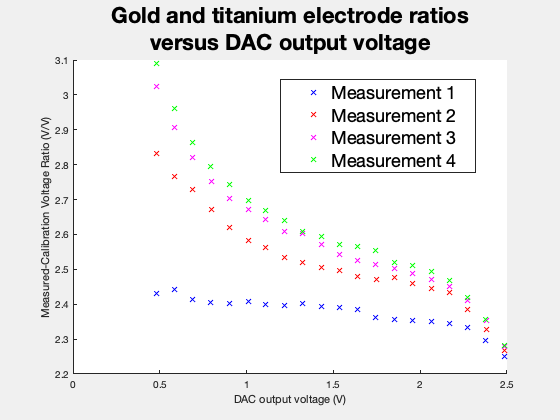

% Au 29.1PSU 20,2C
figure();
hold on
graph("r", 'bx', "150,596,349,848;182,724,421,1028;215,855,497,1199;248,986,571,1373;281,1120,647,1555;314,1251,721,1735;346,1379,794,1906;379,1510,871,2088;412,1642,945,2269;445,1773,1019,2440;478,1905,1095,2617;510,2033,1168,2785;543,2165,1245,2939;576,2297,1321,3111;609,2429,1395,3283;642,2561,1470,3455;674,2688,1543,3616;707,2821,1618,3773;740,2952,1694,3890;773,3085,1768,3978;");
graph("r", 'rx', "150,596,349,988;182,724,421,1164;215,855,496,1353;248,987,571,1526;281,1119,647,1695;314,1251,721,1862;346,1379,794,2035;379,1510,869,2203;412,1642,945,2380;445,1773,1019,2554;478,1906,1096,2736;510,2033,1168,2897;543,2166,1243,3072;576,2297,1319,3267;609,2429,1394,3430;642,2561,1469,3591;674,2689,1542,3751;707,2821,1617,3858;740,2953,1692,3940;773,3084,1767,4007;");
graph("r", 'mx', "150,596,348,1052;182,723,421,1224;215,855,496,1399;248,987,571,1572;281,1119,646,1747;314,1251,721,1927;346,1379,794,2098;379,1510,869,2267;412,1642,944,2456;445,1773,1019,2621;478,1906,1095,2785;510,2033,1168,2951;543,2165,1242,3123;576,2297,1319,3300;609,2428,1394,3467;642,2561,1468,3626;674,2689,1542,3777;707,2822,1618,3902;740,2953,1693,3983;773,3085,1769,4033;");
graph("r", 'gx', "150,596,348,1075;182,723,422,1250;215,855,496,1421;248,986,571,1596;281,1119,646,1773;314,1251,721,1944;346,1379,795,2122;379,1510,869,2293;412,1642,945,2466;445,1774,1020,2646;478,1905,1095,2815;510,2034,1168,2998;543,2165,1243,3173;576,2297,1318,3322;609,2429,1393,3499;642,2561,1468,3661;674,2688,1541,3801;707,2821,1617,3911;740,2952,1691,3983;773,3084,1767,4033;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus18.png");

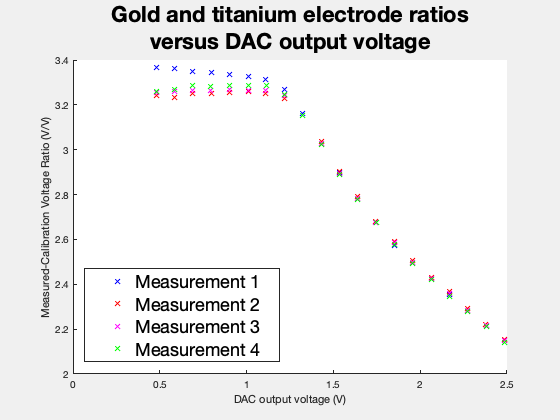

% Ti 29.1PSU 20,2C
figure();
hold on
graph("r", 'bx', "150,596,349,1175;182,724,421,1416;215,856,496,1662;248,987,571,1909;281,1119,646,2154;314,1251,721,2398;346,1379,794,2632;379,1511,869,2840;412,1642,944,2984;445,1773,1018,3092;478,1905,1094,3169;510,2033,1167,3240;543,2165,1242,3323;576,2297,1318,3394;609,2429,1393,3475;642,2561,1469,3554;674,2689,1543,3635;707,2821,1617,3685;740,2953,1692,3749;773,3085,1767,3796;");
graph("r", 'rx', "150,596,349,1131;182,724,423,1368;215,855,497,1616;248,987,572,1859;281,1119,646,2103;314,1251,721,2350;346,1379,794,2581;379,1510,869,2805;412,1642,944,2977;445,1773,1020,3096;478,1905,1096,3181;510,2033,1169,3262;543,2165,1244,3335;576,2298,1319,3419;609,2429,1394,3494;642,2561,1469,3570;674,2689,1542,3649;707,2821,1617,3704;740,2952,1690,3753;773,3084,1767,3807;");
graph("r", 'mx', "150,596,348,1132;182,724,421,1372;215,855,496,1619;248,986,571,1864;281,1119,646,2112;314,1251,722,2358;346,1379,794,2591;379,1510,867,2812;412,1642,944,2976;445,1774,1019,3087;478,1905,1095,3170;510,2033,1168,3251;543,2165,1243,3324;576,2297,1318,3407;609,2429,1393,3480;642,2561,1468,3559;674,2689,1541,3634;707,2820,1615,3685;740,2953,1690,3744;773,3085,1766,3793;");
graph("r", 'gx', "150,596,349,1137;182,723,422,1380;215,855,496,1631;248,986,572,1876;281,1119,646,2124;314,1251,722,2373;346,1380,795,2611;379,1510,870,2824;412,1642,945,2978;445,1773,1020,3085;478,1905,1096,3169;510,2034,1169,3245;543,2166,1244,3328;576,2297,1319,3397;609,2429,1394,3474;642,2561,1469,3557;674,2689,1542,3620;707,2821,1617,3682;740,2953,1692,3742;773,3085,1767,3783;");
title(["Gold and titanium electrode ratios", "versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.15 0.2 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Ti18.png");

%Au 34.8 24.4 29.1
figure();
hold on
[a, b, r_squared] = map("bx", "b-", "150,596,348,881;182,724,421,1037;215,855,495,1218;248,987,570,1374;281,1119,646,1560;314,1250,720,1713;346,1379,793,1860;379,1510,868,2021;412,1642,943,2188;445,1774,1018,2346;478,1906,1093,2517;510,2033,1167,2680;543,2165,1241,2850;576,2297,1316,3021;609,2429,1391,3181;642,2561,1466,3341;674,2689,1539,3491;707,2821,1614,3630;740,2952,1688,3769;773,3084,1763,3865;")

a = 0.1631

b = 2.2026

r_squared = 0.9619

stdC = a;
[a, b, r_squared] = map("rx", "r-", "150,596,348,867;182,724,421,1046;215,856,496,1224;248,987,571,1408;281,1119,646,1580;314,1251,721,1756;346,1379,794,1936;379,1511,869,2103;412,1642,944,2277;445,1774,1020,2467;478,1906,1095,2629;510,2033,1167,2801;543,2165,1243,2964;576,2297,1318,3134;609,2429,1393,3309;642,2561,1468,3477;674,2689,1541,3640;707,2820,1616,3782;740,2952,1690,3895;773,3084,1766,3980;")

a = 0.0656

b = 2.3688

r_squared = 0.9251

C24 = a;
[a, b, r_squared] = map("mx", "m-", "150,596,349,848;182,724,421,1028;215,855,497,1199;248,986,571,1373;281,1120,647,1555;314,1251,721,1735;346,1379,794,1906;379,1510,871,2088;412,1642,945,2269;445,1773,1019,2440;478,1905,1095,2617;510,2033,1168,2785;543,2165,1245,2939;576,2297,1321,3111;609,2429,1395,3283;642,2561,1470,3455;674,2688,1543,3616;707,2821,1618,3773;740,2952,1694,3890;773,3085,1768,3978;")

a = 0.0320

b = 2.3707

r_squared = 0.8319

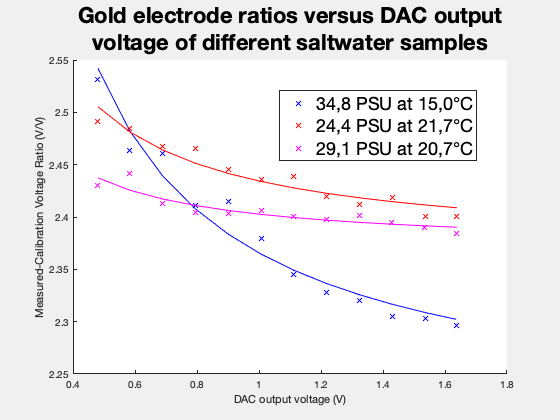

C29 = a;
title(["Gold electrode ratios versus DAC output","voltage of different saltwater samples"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("34,8 PSU at 15,0°C", "", "24,4 PSU at 21.7°C", "", "29,1 PSU at 20.7°C", "", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Au_sweep_analysis.png");

S(C24, stdC, 21.7, 0)

ans = 10.9332

S(C29, stdC, 20.2, 0)

ans = 5.2191

S(C24, C29, 15, 0)

ans = 79.8413

S(C29, C24, 15, 0)

ans = 15.8709

%Ti 34.8 24.4 29.1
figure();
hold on
[a, b, r_squared] = map2("bx", "b-", "150,595,348,1074;182,724,421,1317;215,855,494,1574;248,987,571,1834;281,1119,646,2087;314,1251,720,2341;346,1379,794,2587;379,1511,869,2840;412,1642,943,3088;445,1773,1019,3313;478,1905,1094,3492;510,2033,1167,3628;543,2165,1242,3729;576,2297,1317,3789;609,2429,1391,3842;642,2562,1466,3891;674,2688,1540,3930;707,2821,1614,3967;740,2952,1689,3996;773,3084,1764,4014;")

a = 4.0506

b = 0.6731

r_squared = 0.9950

stdC = a;
[a, b, r_squared] = map2("rx", "r-", "150,596,348,1138;182,724,421,1418;215,855,496,1668;248,987,571,1939;281,1119,646,2201;314,1251,721,2463;346,1379,794,2709;379,1510,869,2949;412,1641,944,3130;445,1773,1019,3249;478,1905,1095,3335;510,2033,1168,3419;543,2165,1242,3495;576,2298,1318,3582;609,2429,1394,3651;642,2561,1468,3717;674,2689,1541,3779;707,2820,1616,3822;740,2952,1691,3863;773,3084,1766,3899;")

a = 3.4400

b = 0.8483

r_squared = 0.9957

S(a, stdC, 21.7, 0)

ans = 24.7953

[a, b, r_squared] = map2("mx", "m-", "150,596,349,1175;182,724,421,1416;215,856,496,1662;248,987,571,1909;281,1119,646,2154;314,1251,721,2398;346,1379,794,2632;379,1511,869,2840;412,1642,944,2984;445,1773,1018,3092;478,1905,1094,3169;510,2033,1167,3240;543,2165,1242,3323;576,2297,1318,3394;609,2429,1393,3475;642,2561,1469,3554;674,2689,1543,3635;707,2821,1617,3685;740,2953,1692,3749;773,3085,1767,3796;")

a = 2.9851

b = 0.9641

r_squared = 0.9981

S(a, stdC, 20.2, 0)

ans = 21.9510

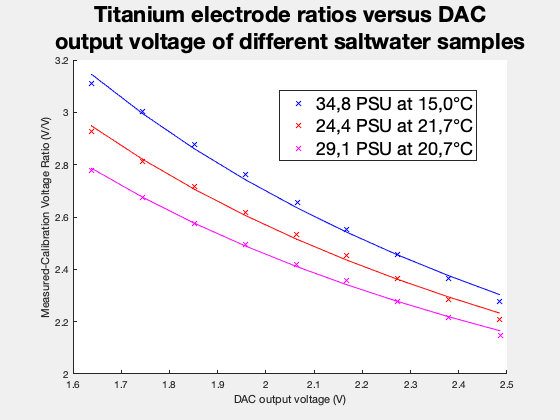

title(["Titanium electrode ratios versus DAC","output voltage of different saltwater samples"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured-Calibration Voltage Ratio (V/V)")
legend("34,8 PSU at 15,0°C", "", "24,4 PSU at 21,7°C", "", "29,1 PSU at 20,7°C", "", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Ti_sweep_analysis.png");

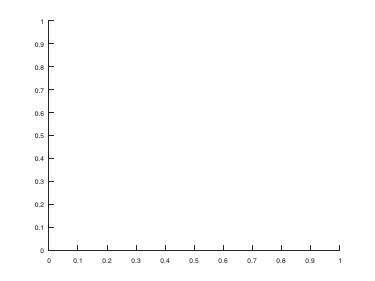

% ??
figure();
hold on

graph("r", 'bx', "");

Index in position 2 exceeds array bounds.

Error in TestingGraphs>graph (line 312)
dac = str2double(data(:,2)) / 4095 * 3.3;

graph("r", 'rx', "");
graph("r", 'mx', "");
graph("r", 'gx', "");
title(["Votlage measured across the gold electrodes", "versus DAC output voltage"], "FontSize", 22);
xlabel("Measurement-Calibration Votlage Ratio (V/V)")
ylabel("Measured electrode voltage (V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Aus16.png");
% Ti 34.8PSU 15C
figure();
hold on
graph("r", 'bx', "");
graph("r", 'rx', "");
graph("r", 'mx', "");
graph("r", 'gx', "");
title(["Votlage measured across the titanium", "electrodes versus DAC output voltage"], "FontSize", 22);
xlabel("DAC output voltage (V)")
ylabel("Measured electrode voltage (V)")
legend("Measurement 1", "Measurement 2", "Measurement 3", "Measurement 4", "Position", [0.5 0.65 0.35, 0.1], "FontSize", 18);
hold off
saveas(gcf, "Report/Figures/Testing/Ti16.png");

function a = graph(item, style, sample)
cols = strsplit(sample, ";");
cols = cols(1:end-1);
data = [];
for i = 1:length(cols)
    data = [data; strsplit(cols(i), ",")];
end
dac = str2double(data(:,2)) / 4095 * 3.3;
measure = str2double(data(:,4)) / 4095 * 3.3 / 11;
ratio = str2double(data(:,4))./str2double(data(:,3));

if (item == "m")
    plot(dac, measure, style)
    set(gcf, 'Visible', 'on');
elseif (item == "r")
    plot(dac, ratio, style)
    set(gcf, 'Visible', 'on');
end
a = 5;
end

function a = graphm(item, style, sample)
cols = strsplit(sample, ";");
cols = cols(1:end-1);
data = [];
for i = 1:length(cols)
    data = [data; strsplit(cols(i), ",")];
    if (str2double(data(i,2)) > 2500)
        break;
    end
end
dac = str2double(data(:,2)) / 4095 * 3.3;
measure = str2double(data(:,4)) / 4095 * 3.3 / 11;
ratio = str2double(data(:,4))./str2double(data(:,3));

if (item == "m")
    plot(dac, measure, style)
    set(gcf, 'Visible', 'on');
elseif (item == "r")
    plot(dac, ratio, style)
    set(gcf, 'Visible', 'on');
end
a = 5;
end

function [a, b, r_squared] = map(points, lines, sample)
    cols = strsplit(sample, ";");
    cols = cols(1:end-1);
    data = [];
    for i = 1:length(cols)
        data = [data; strsplit(cols(i), ",")];
        if (str2double(data(i,2)) > 2000)
            break;
        end
    end
    dac = str2double(data(:,2)) / 4095 * 3.3;
    ratio = str2double(data(:,4))./str2double(data(:,3));

    % curveFitter(dac, ratio)

    ft = fittype("a/x + b", 'option', fitoptions('Method', 'NonlinearLeastSquares', 'StartPoint', [0,0]));
    [fitresult, gof] = fit(dac, ratio, ft);
    
    a = fitresult.a;
    b = fitresult.b;
    r_squared = gof.rsquare;

    plot(dac, ratio, points, dac, fitresult(dac), lines)
    set(gcf, 'Visible', 'on');
end

function [a, b, r_squared] = map2(points, lines, sample)
    cols = strsplit(sample, ";");
    cols = cols(1:end-1);
    data = [];
    for i = 1:length(cols)
        split = strsplit(cols(i), ",");
        if (str2double(split(2)) < 2000)
            continue;
        end
        data = [data; split];
        % if (str2double(data(i,2)) > 2250)
        %     break;
        % end
    end
    dac = str2double(data(:,2)) / 4095 * 3.3;
    ratio = str2double(data(:,4))./str2double(data(:,3));

    % curveFitter(dac, ratio)

    ft = fittype("a/x + b", 'option', fitoptions('Method', 'NonlinearLeastSquares', 'StartPoint', [0,0]));
    [fitresult, gof] = fit(dac, ratio, ft);
    
    a = fitresult.a;
    b = fitresult.b;
    r_squared = gof.rsquare;

    plot(dac, ratio, points, dac, fitresult(dac), lines)
    set(gcf, 'Visible', 'on');
end

function C = S(conductivity, std_conductivity, temperature, pressure)
CONST_K = 0.0162;

CONST_A_0 = 0.0080;
CONST_A_1 = -0.1692;
CONST_A_2 = 25.3851;
CONST_A_3 = 14.0941;
CONST_A_4 = -7.0261;
CONST_A_5 = 2.7081;

CONST_B_0 = 0.0005;
CONST_B_1 = -0.0056;
CONST_B_2 = -0.0066;
CONST_B_3 = -0.0375;
CONST_B_4 = 0.0636;
CONST_B_5 = -0.0144;

CONST_C_0 = 0.6766097;
CONST_C_1 = 0.0200564;
CONST_C_2 = 0.0001104259;
CONST_C_3 = -0.00000069698;
CONST_C_4 = 0.0000000010031;

CONST_D_1 = 0.03426;
CONST_D_2 = 0.0004464;
CONST_D_3 = -0.004215;
CONST_D_4 = -0.003107;

CONST_E_1 = 0.00002070;
CONST_E_2 = -0.000000006370;
CONST_E_3 = 0.000000000000003989;

R = conductivity / std_conductivity;
r_t = CONST_C_0 + CONST_C_1 * temperature + CONST_C_2 * temperature * temperature + CONST_C_3 * temperature * temperature * temperature + CONST_C_4 * temperature * temperature * temperature * temperature;
R_p = 1 + (CONST_E_1 * pressure + CONST_E_2 * pressure * pressure + CONST_E_3 * pressure * pressure * pressure) / (1 + CONST_D_1 * temperature + CONST_D_2 * temperature * temperature + R * (CONST_D_3 + CONST_D_4 * temperature));
R_t = R / (R_p * r_t);
C = CONST_A_0 + CONST_A_1 * (R_t ^ 0.5) + CONST_A_2 * R_t + CONST_A_3 * (R_t ^ 1.5) + CONST_A_4 * R_t * R_t + CONST_A_5 * (R_t ^ 2.5) + (temperature - 15) / (1 + CONST_K * (temperature - 15)) * (CONST_B_0 + CONST_B_1 * (R_t ^ 0.5) + CONST_B_2 * R_t + CONST_B_3 * (R_t ^ 1.5) + CONST_B_4 * R_t * R_t + CONST_B_5 * (R_t ^ 2.5));
end